clc
clear 

% start = tic;
% tic; 

t0=cputime;

%calculate iteration time 
% Initialization and run of differential evolution optimizer.
% A simpler version with fewer explicit parameters is in run0.m
%
% Here for Rosenbrock's function
% Change relevant entries to adapt to your personal applications
%
% The file ofunc.m must also be changed 
% to return the objective function
%
% diary('case4noise0')
% VTR		"Value To Reach" (stop when ofunc < VTR)
% 		VTR =0.000001;
        VTR=-1;

% D		number of parameters of the objective function 
		D = 9; 

% XVmin,XVmax   vector of lower and bounds of initial population
%    		the algorithm seems to work well only if [XVmin,XVmax] 
%    		covers the region where the global minimum is expected
%               *** note: these are no bound constraints!! ***
% 		XVmin = [0 0 0 0 0 0 0.03 2]; 
% 		XVmax = [0.01 0.01 0.005 0.005 0.005 0.012 0.095 3];

%case 4
%         XVmax = [0.04, 0.01, 0.01, 0.01, 0.01, 0.01, 0.01, 0.01, 0.01]; 
%         XVmin = [0.02,    0,    0,    0,    0,    0,    0,    0,    0];

%  case 3        
       XVmax = [0.04  0.008  0.008  0.015  0.008  0.008  0.008  0.015  0.008];
       XVmin = [0.02 -0.002 -0.002 -0.002 -0.002 -0.002 -0.002 -0.002 -0.002]; 

%  case 1       
%         XVmax = [0.035  0.008  0.008  0.008  0.008  0.008  0.008  0.008  0.008];
%         XVmin = [0.023 -0.002 -0.002 -0.002 -0.002 -0.002 -0.002 -0.002 -0.002]; 
 		

% y		problem data vector (remains fixed during optimization)
		y=[]; 

% NP            number of population members
		NP = 30; 

% itermax       maximum number of iterations (generations)
		 itermax = 500; 
       

% F             DE-stepsize F ex [0, 2]
		F = 0.86; 
        factor_method=0;
%F_cr
        F_cr=0.55;
        factor_method_cr=0;
        
% CR            crossover probabililty constant ex [0, 1]
		CR = 0.6; 

% strategy       1 --> DE/best/1/exp           6 --> DE/best/1/bin
%                2 --> DE/rand/1/exp           7 --> DE/rand/1/bin
%                3 --> DE/rand-to-best/1/exp   8 --> DE/rand-to-best/1/bin
%                4 --> DE/best/2/exp           9 --> DE/best/2/bin
%                5 --> DE/rand/2/exp           else  DE/rand/2/bin

		strategy = 10;

% refresh       intermediate output will be produced after "refresh"
%               iterations. No intermediate output will be produced
%               if refresh is < 1
		refresh = 1;    
        
noise=1+rand*0.05;

 
% a1=0.005;a2=0.005;a3=0;a4=0;a5=0;a6=0.01;d=0.06;eps=2.56;

 a1=0.03; a2=0.005; a3=0;  a4=0.01; a5=0;  a6=0;  a7=0;  a8=0.015;  a9=0;
 
% Esexp=direct(a1,a2,a3,a4,a5,a6,d,eps)
Esexp=directH(a1,a2,a3,a4,a5,a6,a7,a8,a9);
% Esexp=directH(ACT,AST)
Esexp=Esexp*noise;
save Esexp Esexp

[Leader_pos_init,x,f,nf] = SADDE('inv1',VTR,D,XVmin,XVmax,y,NP,itermax,F,factor_method,F_cr,factor_method_cr,CR,strategy,refresh);

Iteration: 1,  Best: 0.200593,  F: 0.860000,  CR: 0.600000,  NP: 30


pop =     0.0364    0.0019    0.0014    0.0132    0.0052    0.0004    0.0050    0.0135    0.0080
    0.0279    0.0074    0.0014    0.0032    0.0013    0.0060    0.0047    0.0069    0.0031
    0.0331    0.0039   -0.0007    0.0085    0.0012   -0.0016    0.0052    0.0123    0.0018
    0.0253    0.0031    0.0042    0.0099    0.0038   -0.0001    0.0078    0.0076    0.0074
    0.0298    0.0023   -0.0001    0.0081    0.0047    0.0025    0.0079    0.0071    0.0037
    0.0328    0.0051    0.0014    0.0076    0.0020    0.0035    0.0030    0.0129    0.0017
    0.0304    0.0039   -0.0019    0.0124   -0.0005    0.0055    0.0053    0.0095    0.0002
    0.0239    0.0026    0.0021    0.0107    0.0013   -0.0011    0.0069    0.0118    0.0046
    0.0316    0.0028    0.0041    0.0137    0.0053   -0.0017    0.0014    0.0119    0.0025
    0.0320    0.0028    0.0033    0.0061    0.0054    0.0037    0.0042    0.0084   -0.0013


best(1) = 0.028972
best(2) = 0.004395
best(3) = -0.000697
best(4) = 0.009479
best(5) = -0.000140
best(6) = 0.000116
best(7) = 0.001930
best(8) = 0.013593
best(9) = -0.001457
Iteration: 2,  Best: 0.166105,  F: 0.860000,  CR: 0.600000,  NP: 30


pop =     0.0364    0.0023    0.0014    0.0132   -0.0003    0.0004    0.0035    0.0135    0.0003
    0.0279    0.0065    0.0003    0.0121    0.0048    0.0016    0.0047    0.0069    0.0005
    0.0331    0.0039   -0.0007    0.0085    0.0012   -0.0016    0.0052    0.0123    0.0018
    0.0305    0.0031    0.0014    0.0130    0.0026   -0.0001    0.0078    0.0076   -0.0005
    0.0298    0.0023   -0.0001    0.0081    0.0047    0.0025    0.0079    0.0090    0.0018
    0.0328    0.0054    0.0012    0.0076    0.0020   -0.0014    0.0008    0.0113    0.0017
    0.0304    0.0039   -0.0019    0.0124   -0.0005    0.0055    0.0053    0.0095    0.0002
    0.0239    0.0026    0.0021    0.0132    0.0056   -0.0011    0.0069    0.0148    0.0001
    0.0316    0.0028    0.0041    0.0137    0.0053   -0.0017    0.0014    0.0119    0.0025
    0.0320    0.0028    0.0033    0.0061    0.0054    0.0037    0.0042    0.0084   -0.0013


best(1) = 0.028972
best(2) = 0.004395
best(3) = 0.000406
best(4) = 0.008679
best(5) = 0.000471
best(6) = 0.001040
best(7) = 0.001118
best(8) = 0.014424
best(9) = -0.001522
Iteration: 3,  Best: 0.166105,  F: 0.860000,  CR: 0.600000,  NP: 30


pop =     0.0364    0.0060    0.0005    0.0104   -0.0003    0.0004    0.0035    0.0126    0.0003
    0.0279    0.0065    0.0005    0.0121   -0.0007    0.0016    0.0047    0.0069    0.0005
    0.0331    0.0036   -0.0018    0.0085   -0.0008    0.0015    0.0038    0.0147    0.0018
    0.0264    0.0036   -0.0006    0.0130    0.0011   -0.0001    0.0000    0.0135   -0.0004
    0.0298    0.0023   -0.0001    0.0081    0.0047    0.0025    0.0079    0.0090    0.0018
    0.0328    0.0054    0.0012    0.0076    0.0020   -0.0014    0.0008    0.0113    0.0017
    0.0327    0.0039    0.0025    0.0068    0.0008    0.0020    0.0008    0.0120   -0.0001
    0.0239    0.0040    0.0021    0.0132    0.0010   -0.0011    0.0069    0.0147    0.0001
    0.0316    0.0043    0.0000    0.0084    0.0019   -0.0017   -0.0017    0.0148   -0.0014
    0.0320    0.0028    0.0033    0.0061    0.0054    0.0037    0.0042    0.0084   -0.0013


best(1) = 0.028972
best(2) = 0.004395
best(3) = 0.000406
best(4) = 0.008679
best(5) = 0.000471
best(6) = 0.001040
best(7) = 0.001118
best(8) = 0.014424
best(9) = -0.001522
Iteration: 4,  Best: 0.158452,  F: 0.860000,  CR: 0.600000,  NP: 30


pop =     0.0307    0.0055    0.0020    0.0104    0.0009    0.0007   -0.0002    0.0136    0.0003
    0.0304    0.0038    0.0012    0.0074   -0.0003    0.0023    0.0014    0.0069   -0.0012
    0.0331    0.0036   -0.0018    0.0073    0.0005    0.0015    0.0024    0.0147    0.0018
    0.0264    0.0036   -0.0006    0.0130    0.0011   -0.0001    0.0000    0.0135   -0.0004
    0.0298    0.0023   -0.0001    0.0081    0.0047    0.0025    0.0079    0.0090    0.0018
    0.0328    0.0054    0.0012    0.0076    0.0020   -0.0014    0.0008    0.0113    0.0017
    0.0327    0.0039    0.0025    0.0068    0.0008    0.0020    0.0008    0.0120   -0.0001
    0.0239    0.0040    0.0021    0.0132    0.0010   -0.0011    0.0069    0.0147    0.0001
    0.0316    0.0043    0.0000    0.0084    0.0019   -0.0017   -0.0017    0.0148   -0.0014
    0.0287    0.0028    0.0016    0.0097    0.0019    0.0015    0.0001    0.0109    0.0001


best(1) = 0.030708
best(2) = 0.005491
best(3) = 0.001955
best(4) = 0.010444
best(5) = 0.000948
best(6) = 0.000687
best(7) = -0.000221
best(8) = 0.013582
best(9) = 0.000274
Iteration: 5,  Best: 0.141081,  F: 0.860000,  CR: 0.600000,  NP: 30


pop =     0.0307    0.0055    0.0020    0.0104    0.0009    0.0007   -0.0002    0.0136    0.0003
    0.0304    0.0038    0.0012    0.0074   -0.0003    0.0023    0.0014    0.0069   -0.0012
    0.0331    0.0036   -0.0018    0.0073    0.0005    0.0015    0.0024    0.0147    0.0018
    0.0264    0.0036   -0.0006    0.0130    0.0011   -0.0001    0.0000    0.0135   -0.0004
    0.0298    0.0023    0.0014    0.0081    0.0022    0.0025   -0.0007    0.0131    0.0018
    0.0328    0.0054    0.0012    0.0076    0.0020   -0.0014    0.0008    0.0113    0.0017
    0.0327    0.0039    0.0025    0.0068    0.0008    0.0020    0.0008    0.0120   -0.0001
    0.0239    0.0040    0.0021    0.0132    0.0010   -0.0011    0.0069    0.0147    0.0001
    0.0316    0.0043    0.0000    0.0084    0.0019   -0.0017   -0.0017    0.0148   -0.0014
    0.0287    0.0028    0.0016    0.0097    0.0019    0.0015    0.0001    0.0109    0.0001


best(1) = 0.029239
best(2) = 0.003306
best(3) = 0.000676
best(4) = 0.011428
best(5) = -0.000775
best(6) = 0.001017
best(7) = 0.003380
best(8) = 0.014110
best(9) = -0.000762
Iteration: 6,  Best: 0.141081,  F: 0.860000,  CR: 0.600000,  NP: 30


pop =     0.0307    0.0055    0.0020    0.0104    0.0009    0.0007   -0.0002    0.0136    0.0003
    0.0298    0.0038    0.0027    0.0112   -0.0003    0.0017    0.0022    0.0123   -0.0017
    0.0331    0.0036   -0.0018    0.0073    0.0005    0.0015    0.0024    0.0147    0.0018
    0.0264    0.0036   -0.0006    0.0130    0.0011   -0.0001    0.0000    0.0135   -0.0004
    0.0298    0.0023    0.0014    0.0081    0.0022    0.0025   -0.0007    0.0131    0.0018
    0.0328    0.0047    0.0009    0.0098    0.0005   -0.0014    0.0011    0.0131    0.0004
    0.0327    0.0039    0.0025    0.0068    0.0008    0.0020    0.0008    0.0120   -0.0001
    0.0297    0.0040    0.0021    0.0122   -0.0016   -0.0011    0.0069    0.0128    0.0013
    0.0316    0.0043    0.0000    0.0084    0.0019   -0.0017   -0.0017    0.0148   -0.0014
    0.0285    0.0028    0.0016    0.0097    0.0019   -0.0000    0.0047    0.0138    0.0001


best(1) = 0.029239
best(2) = 0.003306
best(3) = 0.000676
best(4) = 0.011428
best(5) = -0.000775
best(6) = 0.001017
best(7) = 0.003380
best(8) = 0.014110
best(9) = -0.000762
Iteration: 7,  Best: 0.141081,  F: 0.860000,  CR: 0.600000,  NP: 30


pop =     0.0307    0.0055    0.0020    0.0104    0.0009    0.0007   -0.0002    0.0136    0.0003
    0.0298    0.0038    0.0027    0.0112   -0.0003    0.0017    0.0022    0.0123   -0.0017
    0.0331    0.0036   -0.0018    0.0073    0.0005    0.0015    0.0024    0.0147    0.0018
    0.0295    0.0036    0.0010    0.0130   -0.0013    0.0010    0.0000    0.0131    0.0003
    0.0301    0.0023    0.0012    0.0104    0.0022   -0.0011   -0.0007    0.0131    0.0048
    0.0328    0.0047    0.0009    0.0098    0.0005   -0.0014    0.0011    0.0131    0.0004
    0.0327    0.0039    0.0025    0.0068    0.0008    0.0020    0.0008    0.0120   -0.0001
    0.0297    0.0040    0.0012    0.0101    0.0006    0.0016    0.0029    0.0131   -0.0006
    0.0316    0.0043    0.0000    0.0084    0.0019   -0.0017   -0.0017    0.0148   -0.0014
    0.0285    0.0028    0.0016    0.0097    0.0019   -0.0000    0.0047    0.0138    0.0001


best(1) = 0.029239
best(2) = 0.003306
best(3) = 0.000676
best(4) = 0.011428
best(5) = -0.000775
best(6) = 0.001017
best(7) = 0.003380
best(8) = 0.014110
best(9) = -0.000762
Iteration: 8,  Best: 0.122400,  F: 0.860000,  CR: 0.600000,  NP: 30


pop =     0.0307    0.0055    0.0020    0.0104    0.0009    0.0007   -0.0002    0.0136    0.0003
    0.0298    0.0038    0.0027    0.0112   -0.0003    0.0017    0.0022    0.0123   -0.0017
    0.0331    0.0036   -0.0018    0.0073    0.0005    0.0015    0.0024    0.0147    0.0018
    0.0295    0.0036    0.0010    0.0118   -0.0003    0.0014    0.0000    0.0131    0.0009
    0.0293    0.0030    0.0017    0.0101   -0.0014   -0.0011    0.0016    0.0144    0.0002
    0.0295    0.0047   -0.0001    0.0098   -0.0009    0.0007    0.0024    0.0139    0.0004
    0.0327    0.0039    0.0025    0.0068    0.0008    0.0020    0.0008    0.0120   -0.0001
    0.0297    0.0027    0.0017    0.0099    0.0006    0.0020    0.0029    0.0131   -0.0001
    0.0316    0.0043    0.0000    0.0084    0.0019   -0.0017   -0.0017    0.0148   -0.0014
    0.0285    0.0028    0.0016    0.0097    0.0019   -0.0000    0.0047    0.0138    0.0001


best(1) = 0.029317
best(2) = 0.003020
best(3) = 0.001745
best(4) = 0.010064
best(5) = -0.001393
best(6) = -0.001070
best(7) = 0.001627
best(8) = 0.014389
best(9) = 0.000183
Iteration: 9,  Best: 0.122400,  F: 0.860000,  CR: 0.600000,  NP: 30


pop =     0.0307    0.0055    0.0020    0.0104    0.0009    0.0007   -0.0002    0.0136    0.0003
    0.0286    0.0034    0.0007    0.0116   -0.0014   -0.0005    0.0022    0.0141   -0.0008
    0.0315    0.0036    0.0016    0.0073   -0.0010    0.0015    0.0006    0.0147    0.0004
    0.0295    0.0021    0.0010    0.0118    0.0000    0.0014    0.0034    0.0131    0.0009
    0.0293    0.0030    0.0017    0.0101   -0.0014   -0.0011    0.0016    0.0144    0.0002
    0.0295    0.0047   -0.0001    0.0098   -0.0009    0.0007    0.0024    0.0139    0.0004
    0.0327    0.0039    0.0025    0.0068    0.0008    0.0020    0.0008    0.0120   -0.0001
    0.0297    0.0027    0.0017    0.0099    0.0006    0.0020    0.0029    0.0131   -0.0001
    0.0316    0.0043    0.0029    0.0084   -0.0014   -0.0017    0.0006    0.0142   -0.0014
    0.0285    0.0028    0.0016    0.0097    0.0019   -0.0000    0.0047    0.0138    0.0001


best(1) = 0.029317
best(2) = 0.003020
best(3) = 0.001745
best(4) = 0.010064
best(5) = -0.001393
best(6) = -0.001070
best(7) = 0.001627
best(8) = 0.014389
best(9) = 0.000183
Iteration: 10,  Best: 0.122400,  F: 0.860000,  CR: 0.600000,  NP: 30


pop =     0.0307    0.0055    0.0020    0.0104    0.0009    0.0007   -0.0002    0.0136    0.0003
    0.0286    0.0034    0.0007    0.0116   -0.0014   -0.0005    0.0022    0.0141   -0.0008
    0.0315    0.0038    0.0016    0.0083   -0.0010    0.0005    0.0006    0.0147    0.0004
    0.0295    0.0021    0.0010    0.0118    0.0000    0.0014    0.0034    0.0131    0.0009
    0.0293    0.0030    0.0017    0.0101   -0.0014   -0.0011    0.0016    0.0144    0.0002
    0.0295    0.0047   -0.0001    0.0098   -0.0009    0.0007    0.0024    0.0139    0.0004
    0.0327    0.0039    0.0025    0.0068    0.0008    0.0020    0.0008    0.0120   -0.0001
    0.0297    0.0027    0.0017    0.0099    0.0006    0.0020    0.0029    0.0131   -0.0001
    0.0316    0.0043    0.0004    0.0084   -0.0014    0.0009    0.0008    0.0146   -0.0001
    0.0285    0.0028    0.0016    0.0097    0.0019   -0.0000    0.0047    0.0138    0.0001


best(1) = 0.029317
best(2) = 0.003020
best(3) = 0.001745
best(4) = 0.010064
best(5) = -0.001393
best(6) = -0.001070
best(7) = 0.001627
best(8) = 0.014389
best(9) = 0.000183
Iteration: 11,  Best: 0.112113,  F: 0.860000,  CR: 0.600000,  NP: 30


pop =     0.0307    0.0055    0.0020    0.0104    0.0009    0.0007   -0.0002    0.0136    0.0003
    0.0286    0.0034    0.0007    0.0116   -0.0014   -0.0005    0.0022    0.0141   -0.0008
    0.0315    0.0022    0.0011    0.0093   -0.0010    0.0000    0.0035    0.0134    0.0005
    0.0295    0.0021    0.0010    0.0118    0.0000    0.0014    0.0034    0.0131    0.0009
    0.0293    0.0030    0.0017    0.0111   -0.0004   -0.0015    0.0016    0.0141    0.0002
    0.0295    0.0047   -0.0001    0.0098   -0.0009    0.0007    0.0024    0.0139    0.0004
    0.0327    0.0039    0.0025    0.0068    0.0008    0.0020    0.0008    0.0120   -0.0001
    0.0297    0.0027    0.0017    0.0099    0.0006    0.0020    0.0029    0.0131   -0.0001
    0.0316    0.0043    0.0004    0.0084   -0.0014    0.0009    0.0008    0.0146   -0.0001
    0.0289    0.0028    0.0014    0.0097   -0.0008    0.0006    0.0029    0.0138    0.0001


best(1) = 0.029733
best(2) = 0.003162
best(3) = -0.000561
best(4) = 0.009895
best(5) = -0.001224
best(6) = 0.001615
best(7) = 0.001708
best(8) = 0.014650
best(9) = -0.000098
Iteration: 12,  Best: 0.096571,  F: 0.860000,  CR: 0.600000,  NP: 30


pop =     0.0296    0.0039    0.0001    0.0095    0.0009    0.0004    0.0014    0.0140   -0.0004
    0.0298    0.0034   -0.0007    0.0100   -0.0014    0.0023    0.0016    0.0149    0.0010
    0.0315    0.0022    0.0011    0.0093   -0.0010    0.0000    0.0035    0.0134    0.0005
    0.0295    0.0023    0.0010    0.0094    0.0000    0.0004    0.0034    0.0142    0.0006
    0.0293    0.0030    0.0017    0.0111   -0.0004   -0.0015    0.0016    0.0141    0.0002
    0.0295    0.0047   -0.0001    0.0098   -0.0009    0.0007    0.0024    0.0139    0.0004
    0.0306    0.0039    0.0034    0.0093   -0.0012   -0.0001    0.0007    0.0146   -0.0001
    0.0297    0.0018   -0.0007    0.0099    0.0006    0.0020    0.0037    0.0143   -0.0001
    0.0316    0.0043    0.0004    0.0084   -0.0014    0.0009    0.0008    0.0146   -0.0001
    0.0289    0.0030    0.0005    0.0097   -0.0008    0.0006    0.0029    0.0144   -0.0000


best(1) = 0.029756
best(2) = 0.003925
best(3) = -0.000302
best(4) = 0.010858
best(5) = -0.001835
best(6) = 0.000189
best(7) = 0.001225
best(8) = 0.014805
best(9) = 0.000859
Iteration: 13,  Best: 0.085304,  F: 0.528851,  CR: 0.600000,  NP: 30


pop =     0.0296    0.0039    0.0001    0.0095    0.0009    0.0004    0.0014    0.0140   -0.0004
    0.0298    0.0034   -0.0007    0.0100   -0.0014    0.0023    0.0016    0.0149    0.0010
    0.0315    0.0022    0.0011    0.0093   -0.0010    0.0000    0.0035    0.0134    0.0005
    0.0295    0.0045    0.0009    0.0094    0.0028    0.0004    0.0007    0.0142    0.0008
    0.0303    0.0044    0.0017    0.0111   -0.0011   -0.0010    0.0002    0.0147    0.0002
    0.0295    0.0047   -0.0001    0.0098   -0.0009    0.0007    0.0024    0.0139    0.0004
    0.0306    0.0039    0.0034    0.0093   -0.0012   -0.0001    0.0007    0.0146   -0.0001
    0.0297    0.0026   -0.0004    0.0099    0.0006    0.0020    0.0024    0.0144   -0.0001
    0.0310    0.0043    0.0004    0.0084   -0.0011   -0.0006    0.0003    0.0148   -0.0001
    0.0289    0.0030    0.0005    0.0097   -0.0008    0.0006    0.0029    0.0144   -0.0000


best(1) = 0.031003
best(2) = 0.004322
best(3) = 0.000356
best(4) = 0.008385
best(5) = -0.001112
best(6) = -0.000567
best(7) = 0.000310
best(8) = 0.014838
best(9) = -0.000109
Iteration: 14,  Best: 0.085304,  F: 0.528851,  CR: 0.600000,  NP: 30


pop =     0.0296    0.0039    0.0001    0.0095    0.0009    0.0004    0.0014    0.0140   -0.0004
    0.0298    0.0034   -0.0007    0.0100   -0.0014    0.0023    0.0016    0.0149    0.0010
    0.0315    0.0046    0.0011    0.0093   -0.0019    0.0001   -0.0001    0.0134   -0.0015
    0.0295    0.0054   -0.0002    0.0094    0.0003   -0.0000    0.0007    0.0142    0.0008
    0.0303    0.0044    0.0017    0.0111   -0.0011   -0.0010    0.0002    0.0147    0.0002
    0.0298    0.0043   -0.0001    0.0094   -0.0010    0.0007    0.0020    0.0139    0.0018
    0.0321    0.0027    0.0015    0.0093   -0.0016    0.0006    0.0018    0.0146   -0.0008
    0.0297    0.0026   -0.0004    0.0099    0.0006    0.0020    0.0024    0.0144   -0.0001
    0.0310    0.0043    0.0004    0.0084   -0.0011   -0.0006    0.0003    0.0148   -0.0001
    0.0302    0.0030    0.0011    0.0097   -0.0001   -0.0016    0.0007    0.0149   -0.0000


best(1) = 0.031003
best(2) = 0.004322
best(3) = 0.000356
best(4) = 0.008385
best(5) = -0.001112
best(6) = -0.000567
best(7) = 0.000310
best(8) = 0.014838
best(9) = -0.000109
Iteration: 15,  Best: 0.059790,  F: 0.528851,  CR: 0.600000,  NP: 30


pop =     0.0296    0.0039    0.0001    0.0095    0.0009    0.0004    0.0014    0.0140   -0.0004
    0.0298    0.0056   -0.0018    0.0100   -0.0014    0.0002    0.0009    0.0149    0.0011
    0.0308    0.0040    0.0011    0.0090   -0.0008    0.0001   -0.0001    0.0134   -0.0015
    0.0295    0.0054   -0.0002    0.0094    0.0003   -0.0000    0.0007    0.0142    0.0008
    0.0303    0.0044    0.0017    0.0111   -0.0011   -0.0010    0.0002    0.0147    0.0002
    0.0318    0.0043   -0.0001    0.0080   -0.0010    0.0007    0.0014    0.0139    0.0018
    0.0321    0.0027    0.0015    0.0093   -0.0016    0.0006    0.0018    0.0146   -0.0008
    0.0297    0.0034    0.0007    0.0104   -0.0003    0.0005    0.0017    0.0144   -0.0001
    0.0299    0.0043    0.0004    0.0096   -0.0011   -0.0006    0.0003    0.0148   -0.0001
    0.0302    0.0030    0.0011    0.0097   -0.0001   -0.0016    0.0007    0.0149   -0.0000


best(1) = 0.029895
best(2) = 0.004322
best(3) = 0.000356
best(4) = 0.009599
best(5) = -0.001112
best(6) = -0.000567
best(7) = 0.000310
best(8) = 0.014838
best(9) = -0.000109
Iteration: 16,  Best: 0.059790,  F: 0.528851,  CR: 0.600000,  NP: 30


pop =     0.0305    0.0039    0.0001    0.0090    0.0006    0.0004    0.0011    0.0145   -0.0004
    0.0298    0.0056   -0.0018    0.0100   -0.0014    0.0002    0.0009    0.0149    0.0011
    0.0305    0.0040    0.0010    0.0090   -0.0008    0.0004    0.0005    0.0149   -0.0008
    0.0295    0.0053   -0.0005    0.0100   -0.0010    0.0000   -0.0002    0.0142   -0.0014
    0.0300    0.0046    0.0017    0.0110   -0.0011   -0.0010    0.0002    0.0143    0.0002
    0.0318    0.0043    0.0008    0.0080   -0.0006   -0.0005    0.0010    0.0139    0.0018
    0.0295    0.0050    0.0015    0.0095   -0.0003   -0.0004    0.0004    0.0145    0.0004
    0.0297    0.0034    0.0007    0.0104   -0.0003    0.0005    0.0017    0.0144   -0.0001
    0.0299    0.0043    0.0004    0.0096   -0.0011   -0.0006    0.0003    0.0148   -0.0001
    0.0302    0.0030    0.0011    0.0097   -0.0001   -0.0016    0.0007    0.0149   -0.0000


best(1) = 0.029895
best(2) = 0.004322
best(3) = 0.000356
best(4) = 0.009599
best(5) = -0.001112
best(6) = -0.000567
best(7) = 0.000310
best(8) = 0.014838
best(9) = -0.000109
Iteration: 17,  Best: 0.054591,  F: 0.528851,  CR: 0.600000,  NP: 30


pop =     0.0305    0.0039    0.0001    0.0090    0.0006    0.0004    0.0011    0.0145   -0.0004
    0.0297    0.0056   -0.0018    0.0100   -0.0014    0.0004    0.0004    0.0148    0.0011
    0.0305    0.0040    0.0010    0.0090   -0.0008    0.0004    0.0005    0.0149   -0.0008
    0.0295    0.0059   -0.0005    0.0107   -0.0006    0.0000   -0.0003    0.0146   -0.0003
    0.0304    0.0046    0.0017    0.0104   -0.0011   -0.0014    0.0002    0.0148    0.0002
    0.0304    0.0032    0.0008    0.0088   -0.0000    0.0013    0.0018    0.0146    0.0004
    0.0295    0.0050    0.0015    0.0095   -0.0003   -0.0004    0.0004    0.0145    0.0004
    0.0297    0.0034    0.0007    0.0104   -0.0003    0.0005    0.0017    0.0144   -0.0001
    0.0299    0.0043    0.0004    0.0096   -0.0011   -0.0006    0.0003    0.0148   -0.0001
    0.0302    0.0041    0.0008    0.0097   -0.0001   -0.0006    0.0004    0.0149   -0.0009


best(1) = 0.029480
best(2) = 0.005884
best(3) = -0.000477
best(4) = 0.010732
best(5) = -0.000577
best(6) = 0.000045
best(7) = -0.000328
best(8) = 0.014563
best(9) = -0.000262
Iteration: 18,  Best: 0.054591,  F: 0.528851,  CR: 0.600000,  NP: 30


pop =     0.0305    0.0039    0.0001    0.0090    0.0006    0.0004    0.0011    0.0145   -0.0004
    0.0297    0.0056   -0.0018    0.0100   -0.0014    0.0004    0.0004    0.0148    0.0011
    0.0305    0.0040    0.0010    0.0090   -0.0008    0.0004    0.0005    0.0149   -0.0008
    0.0295    0.0059   -0.0005    0.0107   -0.0006    0.0000   -0.0003    0.0146   -0.0003
    0.0304    0.0046    0.0017    0.0104   -0.0011   -0.0014    0.0002    0.0148    0.0002
    0.0304    0.0032    0.0008    0.0088   -0.0000    0.0013    0.0018    0.0146    0.0004
    0.0289    0.0050    0.0007    0.0114   -0.0003   -0.0015   -0.0003    0.0145   -0.0002
    0.0297    0.0034    0.0007    0.0104   -0.0003    0.0005    0.0017    0.0144   -0.0001
    0.0299    0.0043    0.0004    0.0096   -0.0011   -0.0006    0.0003    0.0148   -0.0001
    0.0302    0.0041    0.0008    0.0097   -0.0001   -0.0006    0.0004    0.0149   -0.0009


best(1) = 0.029480
best(2) = 0.005884
best(3) = -0.000477
best(4) = 0.010732
best(5) = -0.000577
best(6) = 0.000045
best(7) = -0.000328
best(8) = 0.014563
best(9) = -0.000262
Iteration: 19,  Best: 0.052785,  F: 0.528851,  CR: 0.600000,  NP: 30


pop =     0.0305    0.0039    0.0001    0.0090    0.0006    0.0004    0.0011    0.0145   -0.0004
    0.0297    0.0056   -0.0018    0.0100   -0.0014    0.0004    0.0004    0.0148    0.0011
    0.0305    0.0040    0.0010    0.0090   -0.0008    0.0004    0.0005    0.0149   -0.0008
    0.0295    0.0059   -0.0005    0.0107   -0.0006    0.0000   -0.0003    0.0146   -0.0003
    0.0304    0.0046    0.0017    0.0104   -0.0011   -0.0014    0.0002    0.0148    0.0002
    0.0304    0.0032    0.0008    0.0088   -0.0000    0.0013    0.0018    0.0146    0.0004
    0.0289    0.0050    0.0007    0.0114   -0.0003   -0.0015   -0.0003    0.0145   -0.0002
    0.0297    0.0034    0.0007    0.0104   -0.0003    0.0005    0.0017    0.0144   -0.0001
    0.0299    0.0043    0.0004    0.0096   -0.0011   -0.0006    0.0003    0.0148   -0.0001
    0.0302    0.0041    0.0008    0.0097   -0.0001   -0.0006    0.0004    0.0149   -0.0009


best(1) = 0.031235
best(2) = 0.004787
best(3) = -0.000586
best(4) = 0.009083
best(5) = -0.000096
best(6) = 0.000803
best(7) = 0.000699
best(8) = 0.014327
best(9) = -0.000092
Iteration: 20,  Best: 0.052785,  F: 0.528851,  CR: 0.600000,  NP: 30


pop =     0.0305    0.0039    0.0001    0.0090    0.0006    0.0004    0.0011    0.0145   -0.0004
    0.0297    0.0056   -0.0018    0.0100   -0.0014    0.0004    0.0004    0.0148    0.0011
    0.0305    0.0040    0.0010    0.0090   -0.0008    0.0004    0.0005    0.0149   -0.0008
    0.0295    0.0059   -0.0005    0.0107   -0.0006    0.0000   -0.0003    0.0146   -0.0003
    0.0304    0.0046    0.0017    0.0104   -0.0011   -0.0014    0.0002    0.0148    0.0002
    0.0304    0.0032    0.0008    0.0088   -0.0000    0.0013    0.0018    0.0146    0.0004
    0.0297    0.0050    0.0007    0.0114    0.0001    0.0006    0.0006    0.0143    0.0004
    0.0309    0.0041    0.0007    0.0091   -0.0003    0.0005    0.0014    0.0144   -0.0001
    0.0299    0.0043    0.0004    0.0096   -0.0011   -0.0006    0.0003    0.0148   -0.0001
    0.0302    0.0041    0.0008    0.0097   -0.0001   -0.0006    0.0004    0.0149   -0.0009


best(1) = 0.031235
best(2) = 0.004787
best(3) = -0.000586
best(4) = 0.009083
best(5) = -0.000096
best(6) = 0.000803
best(7) = 0.000699
best(8) = 0.014327
best(9) = -0.000092
Iteration: 21,  Best: 0.041885,  F: 0.528851,  CR: 0.600000,  NP: 30


pop =     0.0305    0.0039    0.0001    0.0090    0.0006    0.0004    0.0011    0.0145   -0.0004
    0.0302    0.0055   -0.0009    0.0100   -0.0009   -0.0002    0.0004    0.0145    0.0005
    0.0310    0.0044    0.0002    0.0090    0.0002    0.0009    0.0001    0.0149    0.0002
    0.0295    0.0059   -0.0005    0.0107   -0.0006    0.0000   -0.0003    0.0146   -0.0003
    0.0304    0.0046    0.0017    0.0104   -0.0011   -0.0014    0.0002    0.0148    0.0002
    0.0304    0.0032   -0.0008    0.0086   -0.0000    0.0015    0.0016    0.0147   -0.0001
    0.0303    0.0048   -0.0001    0.0114    0.0003    0.0006    0.0006    0.0143    0.0001
    0.0309    0.0041    0.0007    0.0091   -0.0003    0.0005    0.0014    0.0144   -0.0001
    0.0299    0.0043    0.0004    0.0096   -0.0011   -0.0006    0.0003    0.0148   -0.0001
    0.0303    0.0041    0.0008    0.0097   -0.0004   -0.0006    0.0004    0.0145    0.0000


best(1) = 0.030286
best(2) = 0.004073
best(3) = 0.000814
best(4) = 0.009719
best(5) = -0.000396
best(6) = -0.000557
best(7) = 0.000357
best(8) = 0.014510
best(9) = 0.000025
Iteration: 22,  Best: 0.036385,  F: 0.528851,  CR: 0.600000,  NP: 30


pop =     0.0305    0.0036    0.0001    0.0101    0.0006    0.0008    0.0011    0.0145   -0.0004
    0.0302    0.0055   -0.0009    0.0100   -0.0009   -0.0002    0.0004    0.0145    0.0005
    0.0310    0.0044    0.0002    0.0090    0.0002    0.0009    0.0001    0.0149    0.0002
    0.0295    0.0059   -0.0005    0.0107   -0.0006    0.0000   -0.0003    0.0146   -0.0003
    0.0304    0.0046    0.0017    0.0104   -0.0011   -0.0014    0.0002    0.0148    0.0002
    0.0304    0.0038   -0.0006    0.0086    0.0002    0.0006    0.0016    0.0147    0.0003
    0.0306    0.0048   -0.0002    0.0098    0.0003    0.0010    0.0012    0.0142   -0.0001
    0.0303    0.0041    0.0008    0.0098   -0.0003   -0.0001    0.0007    0.0145   -0.0001
    0.0299    0.0043    0.0004    0.0096   -0.0011   -0.0006    0.0003    0.0148   -0.0001
    0.0303    0.0041    0.0008    0.0097   -0.0004   -0.0006    0.0004    0.0145    0.0000


best(1) = 0.030921
best(2) = 0.004123
best(3) = 0.000114
best(4) = 0.009642
best(5) = -0.000021
best(6) = 0.000345
best(7) = 0.000790
best(8) = 0.014327
best(9) = 0.000235
Iteration: 23,  Best: 0.032940,  F: 0.528851,  CR: 0.600000,  NP: 30


pop =     0.0307    0.0044    0.0009    0.0096   -0.0002   -0.0007   -0.0003    0.0148    0.0002
    0.0302    0.0055   -0.0009    0.0100   -0.0009   -0.0002    0.0004    0.0145    0.0005
    0.0308    0.0040   -0.0003    0.0099    0.0006    0.0017    0.0010    0.0141   -0.0002
    0.0295    0.0059   -0.0005    0.0107   -0.0006    0.0000   -0.0003    0.0146   -0.0003
    0.0304    0.0046    0.0017    0.0104   -0.0011   -0.0014    0.0002    0.0148    0.0002
    0.0303    0.0041   -0.0006    0.0098    0.0008    0.0008    0.0012    0.0143    0.0005
    0.0304    0.0043    0.0001    0.0100   -0.0005   -0.0000    0.0005    0.0147    0.0002
    0.0303    0.0041    0.0008    0.0098   -0.0003   -0.0001    0.0007    0.0145   -0.0001
    0.0299    0.0043    0.0004    0.0096   -0.0011   -0.0006    0.0003    0.0148   -0.0001
    0.0303    0.0041    0.0008    0.0097   -0.0004   -0.0006    0.0004    0.0145    0.0000


best(1) = 0.030277
best(2) = 0.005024
best(3) = 0.000261
best(4) = 0.009978
best(5) = -0.000455
best(6) = -0.000688
best(7) = 0.000053
best(8) = 0.014584
best(9) = 0.000562
Iteration: 24,  Best: 0.029943,  F: 0.528851,  CR: 0.600000,  NP: 30


pop =     0.0307    0.0044    0.0009    0.0096   -0.0002   -0.0007   -0.0003    0.0148    0.0002
    0.0302    0.0055   -0.0009    0.0100   -0.0009   -0.0002    0.0004    0.0145    0.0005
    0.0308    0.0040   -0.0003    0.0099    0.0006    0.0017    0.0010    0.0141   -0.0002
    0.0295    0.0059   -0.0005    0.0107   -0.0006    0.0000   -0.0003    0.0146   -0.0003
    0.0308    0.0048    0.0015    0.0097   -0.0011   -0.0015   -0.0002    0.0148    0.0002
    0.0303    0.0041   -0.0006    0.0098    0.0008    0.0008    0.0012    0.0143    0.0005
    0.0304    0.0043    0.0001    0.0100   -0.0005   -0.0000    0.0005    0.0147    0.0002
    0.0303    0.0041    0.0008    0.0098   -0.0003   -0.0001    0.0007    0.0145   -0.0001
    0.0304    0.0047   -0.0001    0.0098   -0.0006   -0.0001    0.0004    0.0146    0.0004
    0.0303    0.0041    0.0008    0.0097   -0.0004   -0.0006    0.0004    0.0145    0.0000


best(1) = 0.030277
best(2) = 0.005024
best(3) = -0.000093
best(4) = 0.010062
best(5) = -0.000455
best(6) = -0.000580
best(7) = -0.000118
best(8) = 0.014670
best(9) = 0.000417
Iteration: 25,  Best: 0.029943,  F: 0.528851,  CR: 0.600000,  NP: 30


pop =     0.0307    0.0044    0.0009    0.0096   -0.0002   -0.0007   -0.0003    0.0148    0.0002
    0.0302    0.0050   -0.0005    0.0106   -0.0003   -0.0002    0.0004    0.0145    0.0006
    0.0308    0.0040   -0.0001    0.0099    0.0004    0.0008    0.0010    0.0143   -0.0002
    0.0298    0.0057   -0.0005    0.0107   -0.0008   -0.0003   -0.0003    0.0145   -0.0003
    0.0305    0.0054    0.0011    0.0097   -0.0008   -0.0015   -0.0002    0.0147    0.0003
    0.0303    0.0041   -0.0006    0.0098    0.0008    0.0008    0.0012    0.0143    0.0005
    0.0304    0.0043    0.0001    0.0100   -0.0005   -0.0000    0.0005    0.0147    0.0002
    0.0303    0.0041    0.0008    0.0098   -0.0003   -0.0001    0.0007    0.0145   -0.0001
    0.0304    0.0047   -0.0001    0.0098   -0.0006   -0.0001    0.0004    0.0146    0.0004
    0.0303    0.0041    0.0008    0.0097   -0.0004   -0.0006    0.0004    0.0145    0.0000


best(1) = 0.030277
best(2) = 0.005024
best(3) = -0.000093
best(4) = 0.010062
best(5) = -0.000455
best(6) = -0.000580
best(7) = -0.000118
best(8) = 0.014670
best(9) = 0.000417
Iteration: 26,  Best: 0.029943,  F: 0.528851,  CR: 0.600000,  NP: 30


pop =     0.0307    0.0044    0.0009    0.0096   -0.0002   -0.0007   -0.0003    0.0148    0.0002
    0.0303    0.0046    0.0000    0.0100    0.0000    0.0002    0.0004    0.0145    0.0006
    0.0308    0.0040   -0.0001    0.0099    0.0004    0.0008    0.0010    0.0143   -0.0002
    0.0298    0.0057   -0.0005    0.0107   -0.0008   -0.0003   -0.0003    0.0145   -0.0003
    0.0305    0.0054    0.0011    0.0097   -0.0008   -0.0015   -0.0002    0.0147    0.0003
    0.0303    0.0041   -0.0006    0.0098    0.0008    0.0008    0.0012    0.0143    0.0005
    0.0304    0.0043    0.0001    0.0100   -0.0005   -0.0000    0.0005    0.0147    0.0002
    0.0303    0.0041    0.0008    0.0098   -0.0003   -0.0001    0.0007    0.0145   -0.0001
    0.0304    0.0047   -0.0001    0.0098   -0.0006   -0.0001    0.0004    0.0146    0.0004
    0.0303    0.0041    0.0008    0.0097   -0.0004   -0.0006    0.0004    0.0145    0.0000


best(1) = 0.030277
best(2) = 0.005024
best(3) = -0.000093
best(4) = 0.010062
best(5) = -0.000455
best(6) = -0.000580
best(7) = -0.000118
best(8) = 0.014670
best(9) = 0.000417
Iteration: 27,  Best: 0.029943,  F: 0.528851,  CR: 0.600000,  NP: 30


pop =     0.0310    0.0050    0.0000    0.0093   -0.0001   -0.0002   -0.0003    0.0145    0.0002
    0.0303    0.0046    0.0000    0.0100    0.0000    0.0002    0.0004    0.0145    0.0006
    0.0308    0.0040   -0.0001    0.0099    0.0004    0.0008    0.0010    0.0143   -0.0002
    0.0298    0.0057   -0.0004    0.0107   -0.0006   -0.0003   -0.0005    0.0145   -0.0003
    0.0305    0.0054    0.0011    0.0097   -0.0008   -0.0015   -0.0002    0.0147    0.0003
    0.0303    0.0047    0.0002    0.0100    0.0008   -0.0001    0.0001    0.0143    0.0005
    0.0304    0.0043    0.0001    0.0100   -0.0005   -0.0000    0.0005    0.0147    0.0002
    0.0303    0.0041    0.0008    0.0098   -0.0003   -0.0001    0.0007    0.0145   -0.0001
    0.0304    0.0047   -0.0001    0.0098   -0.0006   -0.0001    0.0004    0.0146    0.0004
    0.0303    0.0041    0.0008    0.0098   -0.0004   -0.0011    0.0004    0.0150    0.0007


best(1) = 0.030277
best(2) = 0.005024
best(3) = -0.000093
best(4) = 0.010062
best(5) = -0.000455
best(6) = -0.000580
best(7) = -0.000118
best(8) = 0.014670
best(9) = 0.000417
Iteration: 28,  Best: 0.026294,  F: 0.528851,  CR: 0.600000,  NP: 30


pop =     0.0310    0.0050    0.0000    0.0093   -0.0001   -0.0002   -0.0001    0.0146    0.0002
    0.0303    0.0046    0.0000    0.0100    0.0000    0.0002    0.0004    0.0145    0.0006
    0.0308    0.0040   -0.0001    0.0099    0.0004    0.0008    0.0010    0.0143   -0.0002
    0.0306    0.0055   -0.0004    0.0095   -0.0002   -0.0003   -0.0005    0.0144   -0.0003
    0.0303    0.0054    0.0005    0.0101   -0.0005   -0.0010   -0.0001    0.0147    0.0005
    0.0300    0.0047   -0.0000    0.0104   -0.0000   -0.0006    0.0002    0.0143    0.0005
    0.0304    0.0043    0.0001    0.0100   -0.0005   -0.0000    0.0005    0.0147    0.0002
    0.0303    0.0041    0.0008    0.0098   -0.0003   -0.0001    0.0007    0.0145   -0.0001
    0.0304    0.0047   -0.0001    0.0098   -0.0006   -0.0001    0.0004    0.0146    0.0004
    0.0303    0.0041    0.0008    0.0098   -0.0004   -0.0011    0.0004    0.0150    0.0007


best(1) = 0.030205
best(2) = 0.005390
best(3) = 0.000114
best(4) = 0.009968
best(5) = -0.000409
best(6) = -0.000344
best(7) = -0.000339
best(8) = 0.014526
best(9) = -0.000157
Iteration: 29,  Best: 0.026294,  F: 0.528851,  CR: 0.600000,  NP: 30


pop =     0.0310    0.0050    0.0000    0.0093   -0.0001   -0.0002   -0.0001    0.0146    0.0002
    0.0303    0.0046    0.0000    0.0100    0.0000    0.0002    0.0004    0.0145    0.0006
    0.0308    0.0040   -0.0001    0.0099    0.0004    0.0008    0.0010    0.0143   -0.0002
    0.0306    0.0055   -0.0004    0.0095   -0.0002   -0.0003   -0.0005    0.0144   -0.0003
    0.0303    0.0054    0.0005    0.0101   -0.0005   -0.0010   -0.0001    0.0147    0.0005
    0.0299    0.0052   -0.0000    0.0104   -0.0000   -0.0006   -0.0000    0.0146    0.0000
    0.0304    0.0043    0.0001    0.0100   -0.0005   -0.0000    0.0005    0.0147    0.0002
    0.0303    0.0041    0.0008    0.0098   -0.0003   -0.0001    0.0007    0.0145   -0.0001
    0.0304    0.0047   -0.0001    0.0098   -0.0006   -0.0001    0.0004    0.0146    0.0004
    0.0304    0.0045    0.0006    0.0099   -0.0006   -0.0005    0.0002    0.0145    0.0007


best(1) = 0.030205
best(2) = 0.005390
best(3) = 0.000114
best(4) = 0.009968
best(5) = -0.000409
best(6) = -0.000344
best(7) = -0.000339
best(8) = 0.014526
best(9) = -0.000157
Iteration: 30,  Best: 0.026294,  F: 0.528851,  CR: 0.600000,  NP: 30


pop =     0.0310    0.0050    0.0000    0.0093   -0.0001   -0.0002   -0.0001    0.0146    0.0002
    0.0303    0.0046    0.0000    0.0100    0.0000    0.0002    0.0004    0.0145    0.0006
    0.0308    0.0046   -0.0001    0.0099    0.0001    0.0008    0.0007    0.0142   -0.0003
    0.0306    0.0055   -0.0004    0.0095   -0.0002   -0.0003   -0.0005    0.0144   -0.0003
    0.0303    0.0054    0.0002    0.0100   -0.0003   -0.0004   -0.0001    0.0146    0.0004
    0.0299    0.0050    0.0001    0.0104   -0.0002   -0.0006    0.0000    0.0145    0.0000
    0.0307    0.0046    0.0005    0.0100   -0.0005   -0.0004    0.0002    0.0144    0.0001
    0.0303    0.0047    0.0008    0.0098   -0.0003   -0.0003    0.0001    0.0145   -0.0001
    0.0304    0.0047   -0.0001    0.0098   -0.0006   -0.0001    0.0004    0.0146    0.0004
    0.0304    0.0045    0.0006    0.0099   -0.0006   -0.0005    0.0002    0.0145    0.0007


best(1) = 0.030205
best(2) = 0.005390
best(3) = 0.000114
best(4) = 0.009968
best(5) = -0.000409
best(6) = -0.000344
best(7) = -0.000339
best(8) = 0.014526
best(9) = -0.000157
Iteration: 31,  Best: 0.026294,  F: 0.528851,  CR: 0.600000,  NP: 30


pop =     0.0310    0.0050    0.0000    0.0093   -0.0001   -0.0002   -0.0001    0.0146    0.0002
    0.0303    0.0046    0.0000    0.0100    0.0000    0.0002    0.0004    0.0145    0.0006
    0.0308    0.0046   -0.0001    0.0099    0.0001    0.0008    0.0007    0.0142   -0.0003
    0.0306    0.0055   -0.0004    0.0095   -0.0002   -0.0003   -0.0005    0.0144   -0.0003
    0.0303    0.0054    0.0002    0.0100   -0.0003   -0.0004   -0.0001    0.0146    0.0004
    0.0299    0.0050    0.0001    0.0104   -0.0002   -0.0006    0.0000    0.0145    0.0000
    0.0301    0.0050    0.0005    0.0104   -0.0002   -0.0004   -0.0001    0.0148    0.0001
    0.0303    0.0047    0.0008    0.0098   -0.0003   -0.0003    0.0001    0.0145   -0.0001
    0.0304    0.0050   -0.0001    0.0099   -0.0005   -0.0001    0.0002    0.0145    0.0004
    0.0304    0.0045    0.0006    0.0099   -0.0006   -0.0005    0.0002    0.0145    0.0007


best(1) = 0.030205
best(2) = 0.005390
best(3) = 0.000114
best(4) = 0.009968
best(5) = -0.000409
best(6) = -0.000344
best(7) = -0.000339
best(8) = 0.014526
best(9) = -0.000157
Iteration: 32,  Best: 0.024352,  F: 0.218740,  CR: 0.600000,  NP: 30


pop =     0.0310    0.0050    0.0000    0.0093   -0.0001   -0.0002   -0.0001    0.0146    0.0002
    0.0301    0.0046    0.0000    0.0103    0.0000   -0.0001    0.0002    0.0147    0.0006
    0.0308    0.0046   -0.0004    0.0099    0.0001    0.0008    0.0007    0.0143   -0.0001
    0.0306    0.0055   -0.0004    0.0095   -0.0002   -0.0003   -0.0005    0.0144   -0.0003
    0.0303    0.0054    0.0002    0.0100   -0.0003   -0.0004   -0.0001    0.0146    0.0004
    0.0299    0.0050    0.0001    0.0104   -0.0002   -0.0006    0.0000    0.0145    0.0000
    0.0301    0.0050    0.0005    0.0104   -0.0002   -0.0004   -0.0001    0.0148    0.0001
    0.0303    0.0047    0.0008    0.0098   -0.0003   -0.0003    0.0001    0.0145   -0.0001
    0.0304    0.0050   -0.0001    0.0099   -0.0005   -0.0001    0.0002    0.0145    0.0004
    0.0304    0.0045    0.0006    0.0100   -0.0004   -0.0005   -0.0000    0.0146    0.0004


best(1) = 0.030460
best(2) = 0.004745
best(3) = 0.000059
best(4) = 0.009737
best(5) = 0.000151
best(6) = 0.000284
best(7) = 0.000221
best(8) = 0.014444
best(9) = 0.000119
Iteration: 33,  Best: 0.023017,  F: 0.218740,  CR: 0.600000,  NP: 30


pop =     0.0310    0.0050    0.0000    0.0093   -0.0001   -0.0002   -0.0001    0.0146    0.0002
    0.0301    0.0046    0.0000    0.0103    0.0000   -0.0001    0.0002    0.0147    0.0006
    0.0305    0.0045   -0.0000    0.0100   -0.0001    0.0005    0.0006    0.0143   -0.0001
    0.0302    0.0052    0.0002    0.0095   -0.0003   -0.0007   -0.0004    0.0146    0.0002
    0.0303    0.0054    0.0002    0.0100   -0.0003   -0.0004   -0.0001    0.0146    0.0004
    0.0303    0.0047    0.0001    0.0104   -0.0002   -0.0002    0.0004    0.0144    0.0000
    0.0301    0.0053    0.0001    0.0104   -0.0002   -0.0001   -0.0002    0.0148   -0.0002
    0.0303    0.0047    0.0008    0.0098   -0.0003   -0.0003    0.0001    0.0145   -0.0001
    0.0304    0.0050   -0.0001    0.0099   -0.0005   -0.0001    0.0002    0.0145    0.0004
    0.0304    0.0045    0.0006    0.0100   -0.0004   -0.0005   -0.0000    0.0146    0.0004


best(1) = 0.030301
best(2) = 0.005004
best(3) = 0.000171
best(4) = 0.010084
best(5) = -0.000300
best(6) = -0.000392
best(7) = -0.000238
best(8) = 0.014690
best(9) = 0.000100
Iteration: 34,  Best: 0.022215,  F: 0.218740,  CR: 0.600000,  NP: 30


pop =     0.0310    0.0050    0.0000    0.0093   -0.0001   -0.0002   -0.0001    0.0146    0.0002
    0.0301    0.0046    0.0000    0.0103    0.0000   -0.0001    0.0002    0.0147    0.0006
    0.0305    0.0045   -0.0000    0.0100   -0.0001    0.0005    0.0006    0.0143   -0.0001
    0.0302    0.0052    0.0002    0.0095   -0.0003   -0.0007   -0.0004    0.0146    0.0002
    0.0303    0.0050    0.0002    0.0100   -0.0003   -0.0004   -0.0001    0.0147    0.0008
    0.0303    0.0047    0.0001    0.0104   -0.0002   -0.0002    0.0004    0.0144    0.0000
    0.0301    0.0053    0.0001    0.0104   -0.0002   -0.0001   -0.0002    0.0148   -0.0002
    0.0303    0.0047    0.0008    0.0098   -0.0003   -0.0003    0.0001    0.0145   -0.0001
    0.0304    0.0050   -0.0000    0.0099   -0.0003   -0.0002    0.0000    0.0146    0.0002
    0.0304    0.0045    0.0006    0.0100   -0.0004   -0.0005   -0.0000    0.0146    0.0004


best(1) = 0.030446
best(2) = 0.005049
best(3) = -0.000028
best(4) = 0.009904
best(5) = -0.000276
best(6) = -0.000221
best(7) = 0.000024
best(8) = 0.014606
best(9) = 0.000191
Iteration: 35,  Best: 0.022215,  F: 0.218740,  CR: 0.600000,  NP: 30


pop =     0.0305    0.0053    0.0000    0.0097   -0.0003   -0.0008   -0.0004    0.0148    0.0002
    0.0301    0.0046    0.0000    0.0103    0.0000   -0.0001    0.0002    0.0147    0.0006
    0.0305    0.0045   -0.0000    0.0100   -0.0001    0.0005    0.0006    0.0143   -0.0001
    0.0302    0.0052    0.0002    0.0095   -0.0003   -0.0007   -0.0004    0.0146    0.0002
    0.0306    0.0050    0.0002    0.0098   -0.0000   -0.0004   -0.0001    0.0145    0.0004
    0.0303    0.0047    0.0001    0.0104   -0.0002   -0.0002    0.0004    0.0144    0.0000
    0.0301    0.0053    0.0001    0.0104   -0.0002   -0.0001   -0.0002    0.0148   -0.0002
    0.0303    0.0047    0.0008    0.0098   -0.0003   -0.0003    0.0001    0.0145   -0.0001
    0.0304    0.0050   -0.0000    0.0099   -0.0003   -0.0002    0.0000    0.0146    0.0002
    0.0304    0.0045    0.0006    0.0100   -0.0004   -0.0005   -0.0000    0.0146    0.0004


best(1) = 0.030446
best(2) = 0.005049
best(3) = -0.000028
best(4) = 0.009904
best(5) = -0.000276
best(6) = -0.000221
best(7) = 0.000024
best(8) = 0.014606
best(9) = 0.000191
Iteration: 36,  Best: 0.022215,  F: 0.218740,  CR: 0.600000,  NP: 30


pop =     0.0305    0.0053    0.0000    0.0097   -0.0003   -0.0008   -0.0004    0.0148    0.0002
    0.0301    0.0046    0.0000    0.0103    0.0000   -0.0001    0.0002    0.0147    0.0006
    0.0305    0.0045   -0.0000    0.0100   -0.0001    0.0005    0.0006    0.0143   -0.0001
    0.0302    0.0051    0.0002    0.0095   -0.0003   -0.0007   -0.0004    0.0146    0.0002
    0.0306    0.0050    0.0002    0.0098   -0.0000   -0.0004   -0.0001    0.0145    0.0004
    0.0303    0.0047    0.0001    0.0104   -0.0002   -0.0002    0.0004    0.0144    0.0000
    0.0301    0.0053    0.0001    0.0104   -0.0002   -0.0001   -0.0002    0.0148   -0.0002
    0.0303    0.0047    0.0008    0.0098   -0.0003   -0.0003    0.0001    0.0145   -0.0001
    0.0304    0.0050   -0.0000    0.0099   -0.0003   -0.0002    0.0000    0.0146    0.0002
    0.0304    0.0045    0.0006    0.0100   -0.0004   -0.0005   -0.0000    0.0146    0.0004


best(1) = 0.030446
best(2) = 0.005049
best(3) = -0.000028
best(4) = 0.009904
best(5) = -0.000276
best(6) = -0.000221
best(7) = 0.000024
best(8) = 0.014606
best(9) = 0.000191
Iteration: 37,  Best: 0.020249,  F: 0.218740,  CR: 0.600000,  NP: 30


pop =     0.0305    0.0053    0.0000    0.0097   -0.0003   -0.0008   -0.0004    0.0148    0.0002
    0.0301    0.0046    0.0000    0.0103    0.0000   -0.0001    0.0002    0.0147    0.0006
    0.0305    0.0045   -0.0000    0.0100   -0.0001    0.0005    0.0006    0.0143   -0.0001
    0.0303    0.0051    0.0002    0.0095   -0.0002   -0.0007   -0.0004    0.0146    0.0002
    0.0306    0.0050    0.0002    0.0099   -0.0001   -0.0003   -0.0001    0.0145    0.0002
    0.0303    0.0047    0.0001    0.0104   -0.0002   -0.0002    0.0004    0.0144    0.0000
    0.0301    0.0053    0.0001    0.0104   -0.0002   -0.0001   -0.0002    0.0148   -0.0002
    0.0303    0.0047    0.0008    0.0098   -0.0003   -0.0003    0.0001    0.0145   -0.0001
    0.0304    0.0050   -0.0000    0.0099   -0.0003   -0.0002    0.0000    0.0146    0.0002
    0.0304    0.0045    0.0006    0.0100   -0.0004   -0.0005   -0.0000    0.0146    0.0004


best(1) = 0.030297
best(2) = 0.005306
best(3) = 0.000129
best(4) = 0.009963
best(5) = -0.000382
best(6) = -0.000385
best(7) = -0.000246
best(8) = 0.014677
best(9) = -0.000037
Iteration: 38,  Best: 0.017387,  F: 0.218740,  CR: 0.600000,  NP: 30


pop =     0.0305    0.0053    0.0000    0.0097   -0.0003   -0.0008   -0.0004    0.0148    0.0002
    0.0303    0.0048    0.0000    0.0100    0.0000   -0.0001    0.0001    0.0146    0.0001
    0.0303    0.0049   -0.0000    0.0101   -0.0001    0.0005    0.0002    0.0144   -0.0001
    0.0303    0.0051    0.0002    0.0095   -0.0002   -0.0007   -0.0004    0.0146    0.0002
    0.0306    0.0050    0.0002    0.0099   -0.0001   -0.0003   -0.0001    0.0145    0.0002
    0.0303    0.0047    0.0001    0.0104   -0.0002   -0.0002    0.0004    0.0144    0.0000
    0.0301    0.0053    0.0001    0.0104   -0.0002   -0.0001   -0.0002    0.0148   -0.0002
    0.0303    0.0047    0.0008    0.0098   -0.0003   -0.0003    0.0001    0.0145   -0.0001
    0.0302    0.0050    0.0001    0.0100   -0.0003   -0.0002   -0.0002    0.0147    0.0002
    0.0304    0.0045    0.0006    0.0100   -0.0004   -0.0005   -0.0000    0.0146    0.0004


best(1) = 0.030290
best(2) = 0.004829
best(3) = 0.000025
best(4) = 0.009960
best(5) = 0.000020
best(6) = -0.000138
best(7) = 0.000063
best(8) = 0.014599
best(9) = 0.000053
Iteration: 39,  Best: 0.017387,  F: 0.218740,  CR: 0.600000,  NP: 30


pop =     0.0305    0.0053    0.0000    0.0097   -0.0003   -0.0008   -0.0004    0.0148    0.0002
    0.0303    0.0048    0.0000    0.0100    0.0000   -0.0001    0.0001    0.0146    0.0001
    0.0303    0.0049   -0.0000    0.0101   -0.0001    0.0005    0.0002    0.0144   -0.0001
    0.0303    0.0051    0.0002    0.0095   -0.0002   -0.0007   -0.0004    0.0146    0.0002
    0.0305    0.0050    0.0000    0.0099   -0.0002   -0.0003   -0.0001    0.0145    0.0002
    0.0303    0.0047    0.0001    0.0104   -0.0002   -0.0002    0.0004    0.0144    0.0000
    0.0302    0.0053    0.0001    0.0102   -0.0001   -0.0002   -0.0004    0.0147   -0.0002
    0.0303    0.0047    0.0006    0.0097   -0.0003   -0.0003    0.0000    0.0145   -0.0001
    0.0302    0.0050    0.0001    0.0100   -0.0003   -0.0002   -0.0002    0.0147    0.0002
    0.0304    0.0045    0.0005    0.0099   -0.0003   -0.0008   -0.0001    0.0146    0.0004


best(1) = 0.030290
best(2) = 0.004829
best(3) = 0.000025
best(4) = 0.009960
best(5) = 0.000020
best(6) = -0.000138
best(7) = 0.000063
best(8) = 0.014599
best(9) = 0.000053
Iteration: 40,  Best: 0.017387,  F: 0.218740,  CR: 0.600000,  NP: 30


pop =     0.0304    0.0052    0.0002    0.0098   -0.0003   -0.0008   -0.0004    0.0148    0.0002
    0.0303    0.0048    0.0000    0.0100    0.0000   -0.0001    0.0001    0.0146    0.0001
    0.0303    0.0049   -0.0000    0.0101   -0.0001    0.0005    0.0002    0.0144   -0.0001
    0.0302    0.0052    0.0001    0.0095   -0.0001   -0.0003   -0.0005    0.0147    0.0002
    0.0305    0.0050    0.0000    0.0099   -0.0002   -0.0003   -0.0001    0.0145    0.0002
    0.0303    0.0047   -0.0000    0.0101   -0.0002   -0.0003    0.0003    0.0144    0.0002
    0.0302    0.0053    0.0001    0.0102   -0.0001   -0.0002   -0.0004    0.0147   -0.0002
    0.0303    0.0051    0.0006    0.0097   -0.0003   -0.0005   -0.0002    0.0147    0.0001
    0.0302    0.0050    0.0001    0.0100   -0.0003   -0.0002   -0.0002    0.0147    0.0002
    0.0304    0.0045    0.0005    0.0099   -0.0003   -0.0008   -0.0001    0.0146    0.0004


best(1) = 0.030290
best(2) = 0.004829
best(3) = 0.000025
best(4) = 0.009960
best(5) = 0.000020
best(6) = -0.000138
best(7) = 0.000063
best(8) = 0.014599
best(9) = 0.000053
Iteration: 41,  Best: 0.017201,  F: 0.713596,  CR: 0.600000,  NP: 30


pop =     0.0304    0.0052    0.0002    0.0098   -0.0003   -0.0008   -0.0004    0.0148    0.0002
    0.0303    0.0048    0.0000    0.0100    0.0000   -0.0001    0.0001    0.0146    0.0001
    0.0302    0.0050   -0.0001    0.0101    0.0001    0.0002    0.0000    0.0144   -0.0001
    0.0302    0.0052    0.0000    0.0099    0.0001   -0.0001   -0.0001    0.0147    0.0002
    0.0302    0.0048    0.0003    0.0099   -0.0001   -0.0003    0.0001    0.0146    0.0002
    0.0303    0.0047   -0.0000    0.0101   -0.0002   -0.0003    0.0003    0.0144    0.0002
    0.0302    0.0053    0.0001    0.0102   -0.0001   -0.0002   -0.0004    0.0147   -0.0002
    0.0305    0.0049    0.0006    0.0098   -0.0003   -0.0005   -0.0002    0.0146   -0.0000
    0.0302    0.0050    0.0001    0.0100   -0.0003   -0.0002   -0.0002    0.0147    0.0002
    0.0304    0.0045    0.0005    0.0099   -0.0003   -0.0008   -0.0001    0.0146    0.0004


best(1) = 0.030341
best(2) = 0.004755
best(3) = -0.000054
best(4) = 0.009864
best(5) = 0.000070
best(6) = 0.000196
best(7) = 0.000221
best(8) = 0.014689
best(9) = -0.000150
Iteration: 42,  Best: 0.017149,  F: 0.713596,  CR: 0.600000,  NP: 30


pop =     0.0304    0.0052    0.0002    0.0098   -0.0003   -0.0008   -0.0004    0.0148    0.0002
    0.0303    0.0048    0.0000    0.0100    0.0000   -0.0001    0.0001    0.0146    0.0001
    0.0302    0.0050   -0.0001    0.0101    0.0001    0.0002    0.0000    0.0144   -0.0001
    0.0302    0.0052    0.0000    0.0099    0.0001   -0.0001   -0.0001    0.0147    0.0002
    0.0302    0.0047    0.0003    0.0099   -0.0001   -0.0003    0.0001    0.0147   -0.0000
    0.0303    0.0047   -0.0000    0.0101   -0.0002   -0.0003    0.0003    0.0144    0.0002
    0.0302    0.0053    0.0001    0.0102   -0.0001   -0.0002   -0.0004    0.0147   -0.0002
    0.0305    0.0049    0.0006    0.0098   -0.0003   -0.0005   -0.0002    0.0146   -0.0000
    0.0302    0.0050    0.0001    0.0100   -0.0003   -0.0002   -0.0002    0.0147    0.0002
    0.0304    0.0045    0.0005    0.0099   -0.0002   -0.0004    0.0000    0.0146    0.0002


best(1) = 0.030341
best(2) = 0.004755
best(3) = 0.000139
best(4) = 0.009914
best(5) = 0.000070
best(6) = 0.000155
best(7) = 0.000221
best(8) = 0.014689
best(9) = -0.000150
Iteration: 43,  Best: 0.017149,  F: 0.713596,  CR: 0.600000,  NP: 30


pop =     0.0303    0.0049    0.0002    0.0098   -0.0003   -0.0002   -0.0000    0.0148    0.0002
    0.0303    0.0048    0.0000    0.0100    0.0000   -0.0001    0.0001    0.0146    0.0001
    0.0302    0.0050   -0.0001    0.0101    0.0001    0.0002    0.0000    0.0144   -0.0001
    0.0302    0.0052    0.0000    0.0099    0.0001   -0.0001   -0.0001    0.0147    0.0002
    0.0302    0.0047    0.0003    0.0099   -0.0001   -0.0003    0.0001    0.0147   -0.0000
    0.0302    0.0047   -0.0000    0.0099   -0.0001    0.0001    0.0003    0.0146   -0.0000
    0.0302    0.0053    0.0001    0.0102   -0.0001   -0.0002   -0.0004    0.0147   -0.0002
    0.0305    0.0049    0.0006    0.0098   -0.0003   -0.0005   -0.0002    0.0146   -0.0000
    0.0302    0.0050    0.0001    0.0100   -0.0003   -0.0002   -0.0002    0.0147    0.0002
    0.0304    0.0045    0.0005    0.0099   -0.0002   -0.0004    0.0000    0.0146    0.0002


best(1) = 0.030341
best(2) = 0.004755
best(3) = 0.000139
best(4) = 0.009914
best(5) = 0.000070
best(6) = 0.000155
best(7) = 0.000221
best(8) = 0.014689
best(9) = -0.000150
Iteration: 44,  Best: 0.015123,  F: 0.713596,  CR: 0.600000,  NP: 30


pop =     0.0303    0.0049    0.0002    0.0098   -0.0003   -0.0002   -0.0000    0.0148    0.0002
    0.0303    0.0048    0.0000    0.0100    0.0000   -0.0001    0.0001    0.0146    0.0001
    0.0302    0.0049   -0.0002    0.0099    0.0001    0.0004    0.0001    0.0148   -0.0001
    0.0302    0.0052    0.0000    0.0099    0.0001   -0.0001   -0.0001    0.0147    0.0002
    0.0302    0.0047    0.0004    0.0099   -0.0000   -0.0004    0.0001    0.0148   -0.0001
    0.0302    0.0047   -0.0000    0.0099   -0.0001    0.0001    0.0003    0.0146   -0.0000
    0.0302    0.0053    0.0001    0.0102   -0.0001   -0.0002   -0.0004    0.0147   -0.0002
    0.0305    0.0049    0.0006    0.0098   -0.0002   -0.0005   -0.0002    0.0146   -0.0000
    0.0302    0.0050    0.0001    0.0100   -0.0003   -0.0002   -0.0002    0.0147    0.0002
    0.0304    0.0045    0.0005    0.0099   -0.0002   -0.0004    0.0000    0.0146    0.0002


best(1) = 0.030224
best(2) = 0.004903
best(3) = -0.000205
best(4) = 0.009901
best(5) = 0.000071
best(6) = 0.000350
best(7) = 0.000090
best(8) = 0.014769
best(9) = -0.000058
Iteration: 45,  Best: 0.013386,  F: 0.713596,  CR: 0.600000,  NP: 30


pop =     0.0303    0.0049    0.0002    0.0098   -0.0003   -0.0002   -0.0000    0.0148    0.0002
    0.0301    0.0051   -0.0001    0.0100    0.0000    0.0002    0.0000    0.0147    0.0001
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002   -0.0001    0.0148    0.0001
    0.0302    0.0051    0.0000    0.0099    0.0001   -0.0001   -0.0001    0.0147    0.0002
    0.0302    0.0047    0.0001    0.0101   -0.0002    0.0000    0.0003    0.0148   -0.0000
    0.0302    0.0047   -0.0000    0.0099   -0.0001    0.0001    0.0003    0.0146   -0.0000
    0.0302    0.0053    0.0001    0.0102   -0.0001   -0.0002   -0.0004    0.0147   -0.0002
    0.0305    0.0049    0.0006    0.0098   -0.0002   -0.0005   -0.0002    0.0146   -0.0000
    0.0302    0.0050    0.0001    0.0100   -0.0003   -0.0002   -0.0002    0.0147    0.0002
    0.0304    0.0045    0.0005    0.0099   -0.0002   -0.0004    0.0000    0.0146    0.0002


best(1) = 0.030224
best(2) = 0.005096
best(3) = -0.000171
best(4) = 0.009915
best(5) = 0.000071
best(6) = 0.000203
best(7) = -0.000054
best(8) = 0.014769
best(9) = 0.000093
Iteration: 46,  Best: 0.013248,  F: 0.713596,  CR: 0.600000,  NP: 30


pop =     0.0303    0.0049    0.0002    0.0098   -0.0003   -0.0002   -0.0000    0.0148    0.0002
    0.0301    0.0051   -0.0001    0.0100    0.0000    0.0002    0.0000    0.0149    0.0001
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002   -0.0001    0.0148    0.0001
    0.0302    0.0051    0.0000    0.0099    0.0001   -0.0001   -0.0001    0.0147    0.0002
    0.0302    0.0047    0.0001    0.0101   -0.0002    0.0000    0.0003    0.0148   -0.0000
    0.0302    0.0047   -0.0000    0.0099   -0.0001    0.0001    0.0003    0.0147    0.0002
    0.0300    0.0053    0.0001    0.0102   -0.0001   -0.0002   -0.0004    0.0147    0.0000
    0.0305    0.0049    0.0006    0.0098   -0.0002   -0.0005   -0.0002    0.0146   -0.0000
    0.0302    0.0050    0.0001    0.0100   -0.0003   -0.0002   -0.0002    0.0147    0.0002
    0.0304    0.0045    0.0005    0.0099   -0.0002   -0.0004    0.0000    0.0146    0.0002


best(1) = 0.030146
best(2) = 0.005122
best(3) = -0.000121
best(4) = 0.009960
best(5) = 0.000020
best(6) = 0.000223
best(7) = 0.000040
best(8) = 0.014861
best(9) = 0.000053
Iteration: 47,  Best: 0.013248,  F: 0.864855,  CR: 0.600000,  NP: 30


pop =     0.0303    0.0049    0.0002    0.0098   -0.0003   -0.0002   -0.0000    0.0148    0.0002
    0.0301    0.0051   -0.0001    0.0100    0.0000    0.0002    0.0000    0.0149    0.0001
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002   -0.0001    0.0148    0.0001
    0.0302    0.0051    0.0000    0.0099    0.0001   -0.0001   -0.0001    0.0147    0.0002
    0.0302    0.0047    0.0001    0.0101   -0.0002    0.0000    0.0003    0.0148   -0.0000
    0.0302    0.0047   -0.0000    0.0099   -0.0001    0.0001    0.0003    0.0147    0.0002
    0.0300    0.0053    0.0001    0.0102   -0.0001   -0.0002   -0.0004    0.0147    0.0000
    0.0305    0.0049    0.0006    0.0098   -0.0002   -0.0005   -0.0002    0.0146   -0.0000
    0.0302    0.0050    0.0001    0.0100   -0.0003   -0.0002   -0.0002    0.0147    0.0002
    0.0304    0.0045    0.0005    0.0099   -0.0002   -0.0004    0.0000    0.0146    0.0002


best(1) = 0.030146
best(2) = 0.005122
best(3) = -0.000121
best(4) = 0.009960
best(5) = 0.000020
best(6) = 0.000223
best(7) = 0.000040
best(8) = 0.014861
best(9) = 0.000053
Iteration: 48,  Best: 0.013248,  F: 0.181060,  CR: 0.600000,  NP: 30


pop =     0.0303    0.0049    0.0002    0.0098   -0.0003   -0.0002   -0.0000    0.0148    0.0002
    0.0301    0.0051   -0.0001    0.0100    0.0000    0.0002    0.0000    0.0149    0.0001
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002   -0.0001    0.0148    0.0001
    0.0302    0.0051    0.0000    0.0099    0.0001   -0.0001   -0.0001    0.0147    0.0002
    0.0302    0.0047    0.0001    0.0101   -0.0002    0.0000    0.0003    0.0148   -0.0000
    0.0302    0.0047   -0.0000    0.0099   -0.0001    0.0001    0.0003    0.0147    0.0002
    0.0300    0.0053    0.0001    0.0102   -0.0001   -0.0002   -0.0004    0.0147    0.0000
    0.0305    0.0049    0.0003    0.0098   -0.0003   -0.0002    0.0001    0.0147   -0.0001
    0.0303    0.0051   -0.0001    0.0098   -0.0003   -0.0002   -0.0001    0.0147    0.0002
    0.0304    0.0045    0.0005    0.0099   -0.0002   -0.0004    0.0000    0.0146    0.0002


best(1) = 0.030146
best(2) = 0.005122
best(3) = -0.000121
best(4) = 0.009960
best(5) = 0.000020
best(6) = 0.000223
best(7) = 0.000040
best(8) = 0.014861
best(9) = 0.000053
Iteration: 49,  Best: 0.013248,  F: 0.181060,  CR: 0.600000,  NP: 30


pop =     0.0303    0.0049    0.0002    0.0098   -0.0003   -0.0002   -0.0000    0.0148    0.0002
    0.0301    0.0051   -0.0001    0.0100    0.0000    0.0002    0.0000    0.0149    0.0001
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002   -0.0001    0.0148    0.0001
    0.0302    0.0051    0.0000    0.0099    0.0001   -0.0001   -0.0001    0.0147    0.0002
    0.0302    0.0048    0.0001    0.0099   -0.0002    0.0000    0.0002    0.0148   -0.0001
    0.0302    0.0047   -0.0000    0.0099   -0.0001    0.0001    0.0003    0.0147    0.0002
    0.0301    0.0053    0.0000    0.0102   -0.0002   -0.0002   -0.0001    0.0148   -0.0002
    0.0305    0.0049    0.0003    0.0098   -0.0003   -0.0002    0.0001    0.0147   -0.0001
    0.0303    0.0051   -0.0001    0.0098   -0.0003   -0.0002   -0.0001    0.0147    0.0002
    0.0304    0.0045    0.0003    0.0099   -0.0002   -0.0002    0.0002    0.0146    0.0002


best(1) = 0.030146
best(2) = 0.005122
best(3) = -0.000121
best(4) = 0.009960
best(5) = 0.000020
best(6) = 0.000223
best(7) = 0.000040
best(8) = 0.014861
best(9) = 0.000053
Iteration: 50,  Best: 0.013248,  F: 0.181060,  CR: 0.600000,  NP: 30


pop =     0.0303    0.0049    0.0002    0.0098   -0.0003   -0.0002   -0.0000    0.0148    0.0002
    0.0301    0.0051   -0.0001    0.0100    0.0000    0.0002    0.0000    0.0149    0.0001
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002   -0.0001    0.0148    0.0001
    0.0302    0.0051    0.0000    0.0099    0.0001   -0.0001   -0.0001    0.0147    0.0002
    0.0302    0.0051   -0.0000    0.0099   -0.0002   -0.0000    0.0000    0.0148   -0.0001
    0.0302    0.0047   -0.0000    0.0099   -0.0001    0.0001    0.0003    0.0148    0.0002
    0.0301    0.0053    0.0000    0.0102   -0.0002   -0.0002   -0.0001    0.0148   -0.0002
    0.0305    0.0046    0.0003    0.0098   -0.0003   -0.0002    0.0003    0.0146   -0.0002
    0.0303    0.0051   -0.0001    0.0098   -0.0003   -0.0002   -0.0001    0.0147    0.0002
    0.0304    0.0045    0.0003    0.0099   -0.0002   -0.0002    0.0002    0.0146    0.0002


best(1) = 0.030146
best(2) = 0.005122
best(3) = -0.000121
best(4) = 0.009960
best(5) = 0.000020
best(6) = 0.000223
best(7) = 0.000040
best(8) = 0.014861
best(9) = 0.000053
Iteration: 51,  Best: 0.013248,  F: 0.181060,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0303    0.0049    0.0002    0.0098   -0.0003   -0.0002   -0.0000    0.0148    0.0002
    0.0301    0.0051   -0.0001    0.0100    0.0000    0.0002    0.0000    0.0149    0.0001
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002   -0.0001    0.0148    0.0001
    0.0302    0.0051    0.0000    0.0099    0.0001   -0.0001   -0.0001    0.0147    0.0002
    0.0302    0.0051   -0.0000    0.0099   -0.0002   -0.0000    0.0000    0.0148   -0.0001
    0.0302    0.0047   -0.0000    0.0099   -0.0001    0.0001    0.0003    0.0148    0.0002
    0.0301    0.0053    0.0000    0.0102   -0.0002   -0.0002   -0.0001    0.0148   -0.0002
    0.0304    0.0046    0.0003    0.0098   -0.0002   -0.0002    0.0001    0.0146    0.0000
    0.0302    0.0051   -0.0001    0.0099   -0.0003   -0.0002   -0.0001    0.0148    0.0002
    0.0304    0.0045    0.0003    0.0099   -0.0002   -0.0002    0.0002    0.0146    0.0002


best(1) = 0.030146
best(2) = 0.005122
best(3) = -0.000121
best(4) = 0.009960
best(5) = 0.000020
best(6) = 0.000223
best(7) = 0.000040
best(8) = 0.014861
best(9) = 0.000053
Iteration: 52,  Best: 0.012950,  F: 0.181060,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0303    0.0049    0.0002    0.0098   -0.0003   -0.0002   -0.0000    0.0148    0.0002
    0.0301    0.0051   -0.0001    0.0100    0.0000    0.0002    0.0000    0.0149    0.0001
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002    0.0000    0.0148    0.0000
    0.0302    0.0051    0.0000    0.0099    0.0001   -0.0001   -0.0001    0.0147    0.0002
    0.0302    0.0051   -0.0000    0.0099   -0.0002   -0.0000    0.0000    0.0148   -0.0001
    0.0302    0.0047   -0.0000    0.0099   -0.0001    0.0001    0.0003    0.0148    0.0002
    0.0301    0.0053    0.0000    0.0102   -0.0002   -0.0002   -0.0001    0.0148   -0.0002
    0.0303    0.0049    0.0003    0.0099   -0.0001   -0.0002    0.0001    0.0146    0.0000
    0.0302    0.0051   -0.0001    0.0099   -0.0003   -0.0002   -0.0001    0.0148    0.0002
    0.0304    0.0045    0.0003    0.0099   -0.0002   -0.0002    0.0002    0.0146    0.0002


best(1) = 0.030173
best(2) = 0.005082
best(3) = -0.000231
best(4) = 0.009915
best(5) = 0.000071
best(6) = 0.000203
best(7) = 0.000005
best(8) = 0.014769
best(9) = 0.000039
Iteration: 53,  Best: 0.012950,  F: 0.181060,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0303    0.0049   -0.0000    0.0098   -0.0003   -0.0002   -0.0000    0.0148    0.0002
    0.0301    0.0051   -0.0001    0.0100    0.0000    0.0002    0.0000    0.0149    0.0001
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002    0.0000    0.0148    0.0000
    0.0302    0.0051    0.0000    0.0099    0.0001   -0.0001   -0.0001    0.0147    0.0002
    0.0302    0.0051   -0.0000    0.0099   -0.0002   -0.0000    0.0000    0.0148   -0.0001
    0.0302    0.0047   -0.0000    0.0099   -0.0001    0.0001    0.0003    0.0148    0.0002
    0.0301    0.0053   -0.0001    0.0102   -0.0003   -0.0001   -0.0001    0.0149   -0.0001
    0.0303    0.0048    0.0003    0.0099   -0.0000   -0.0002    0.0001    0.0146    0.0001
    0.0302    0.0051   -0.0001    0.0099   -0.0003   -0.0002   -0.0001    0.0148    0.0002
    0.0304    0.0045    0.0003    0.0099   -0.0002   -0.0002    0.0002    0.0146    0.0002


best(1) = 0.030173
best(2) = 0.005082
best(3) = -0.000231
best(4) = 0.009915
best(5) = 0.000071
best(6) = 0.000203
best(7) = 0.000005
best(8) = 0.014769
best(9) = 0.000039
Iteration: 54,  Best: 0.012950,  F: 0.181060,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0303    0.0049   -0.0000    0.0098   -0.0003   -0.0002   -0.0000    0.0148    0.0002
    0.0301    0.0051   -0.0001    0.0100    0.0000    0.0002    0.0000    0.0149    0.0001
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002    0.0000    0.0148    0.0000
    0.0302    0.0051    0.0000    0.0099   -0.0000   -0.0001   -0.0001    0.0147    0.0002
    0.0303    0.0051   -0.0000    0.0098   -0.0002   -0.0000    0.0000    0.0148   -0.0001
    0.0302    0.0047   -0.0000    0.0099   -0.0001    0.0001    0.0003    0.0148    0.0002
    0.0301    0.0053   -0.0001    0.0102   -0.0003   -0.0001   -0.0001    0.0149   -0.0001
    0.0303    0.0049    0.0001    0.0099   -0.0000   -0.0002    0.0001    0.0146    0.0002
    0.0302    0.0051   -0.0001    0.0099   -0.0003   -0.0002   -0.0001    0.0148    0.0002
    0.0304    0.0045    0.0003    0.0099   -0.0002   -0.0002    0.0002    0.0146    0.0002


best(1) = 0.030173
best(2) = 0.005082
best(3) = -0.000231
best(4) = 0.009915
best(5) = 0.000071
best(6) = 0.000203
best(7) = 0.000005
best(8) = 0.014769
best(9) = 0.000039
Iteration: 55,  Best: 0.012392,  F: 0.181060,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0303    0.0048    0.0001    0.0098   -0.0003   -0.0002    0.0002    0.0148    0.0002
    0.0301    0.0051   -0.0001    0.0100    0.0000    0.0002    0.0000    0.0149    0.0001
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002    0.0000    0.0148    0.0000
    0.0302    0.0051    0.0000    0.0099   -0.0000   -0.0001   -0.0001    0.0147    0.0002
    0.0303    0.0051   -0.0000    0.0098   -0.0002   -0.0000    0.0000    0.0148   -0.0001
    0.0302    0.0047   -0.0000    0.0099   -0.0001    0.0001    0.0003    0.0148    0.0002
    0.0301    0.0053   -0.0001    0.0102   -0.0003   -0.0001   -0.0001    0.0149   -0.0001
    0.0303    0.0049    0.0001    0.0099   -0.0000   -0.0002    0.0001    0.0146    0.0002
    0.0302    0.0051   -0.0001    0.0099   -0.0003   -0.0002   -0.0001    0.0148    0.0002
    0.0304    0.0045    0.0003    0.0099   -0.0002   -0.0002    0.0002    0.0146    0.0002


best(1) = 0.030255
best(2) = 0.004856
best(3) = -0.000051
best(4) = 0.009910
best(5) = 0.000057
best(6) = 0.000076
best(7) = 0.000151
best(8) = 0.014757
best(9) = 0.000010
Iteration: 56,  Best: 0.012392,  F: 0.181060,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0303    0.0047    0.0001    0.0099   -0.0000   -0.0002    0.0002    0.0147    0.0003
    0.0301    0.0051   -0.0001    0.0100    0.0000    0.0002    0.0000    0.0149    0.0001
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002    0.0000    0.0148    0.0000
    0.0302    0.0051    0.0000    0.0099   -0.0000   -0.0001   -0.0001    0.0147    0.0002
    0.0303    0.0051   -0.0000    0.0098   -0.0002   -0.0000    0.0000    0.0148   -0.0001
    0.0302    0.0047   -0.0000    0.0099   -0.0001    0.0001    0.0003    0.0148    0.0002
    0.0301    0.0053   -0.0001    0.0102   -0.0003   -0.0001   -0.0001    0.0149   -0.0001
    0.0303    0.0049    0.0001    0.0099   -0.0000   -0.0002    0.0001    0.0146    0.0002
    0.0302    0.0051   -0.0001    0.0099   -0.0003   -0.0002   -0.0001    0.0148    0.0002
    0.0304    0.0045    0.0003    0.0099   -0.0002   -0.0002    0.0002    0.0146    0.0002


best(1) = 0.030255
best(2) = 0.004856
best(3) = -0.000051
best(4) = 0.009910
best(5) = 0.000057
best(6) = 0.000076
best(7) = 0.000151
best(8) = 0.014757
best(9) = 0.000010
Iteration: 57,  Best: 0.012392,  F: 0.181060,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0303    0.0047    0.0001    0.0099   -0.0000   -0.0002    0.0002    0.0147    0.0003
    0.0301    0.0051   -0.0001    0.0100    0.0000    0.0002    0.0000    0.0149    0.0001
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002    0.0000    0.0148    0.0000
    0.0302    0.0051    0.0000    0.0099   -0.0000   -0.0001   -0.0001    0.0147    0.0002
    0.0303    0.0051   -0.0000    0.0098   -0.0002   -0.0000    0.0000    0.0148   -0.0001
    0.0302    0.0047   -0.0000    0.0099   -0.0001    0.0001    0.0003    0.0148    0.0002
    0.0301    0.0053   -0.0001    0.0102   -0.0003   -0.0001   -0.0001    0.0149   -0.0001
    0.0303    0.0049    0.0001    0.0099   -0.0000   -0.0002    0.0001    0.0146    0.0002
    0.0302    0.0051   -0.0001    0.0099   -0.0003   -0.0002   -0.0001    0.0148    0.0002
    0.0304    0.0045    0.0003    0.0099   -0.0002   -0.0002    0.0002    0.0146    0.0002


best(1) = 0.030255
best(2) = 0.004856
best(3) = -0.000051
best(4) = 0.009910
best(5) = 0.000057
best(6) = 0.000076
best(7) = 0.000151
best(8) = 0.014757
best(9) = 0.000010
Iteration: 58,  Best: 0.012127,  F: 0.181060,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0303    0.0048    0.0001    0.0099   -0.0000   -0.0002    0.0002    0.0148    0.0002
    0.0301    0.0051   -0.0001    0.0100    0.0000    0.0002    0.0000    0.0149    0.0001
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002    0.0000    0.0148    0.0000
    0.0302    0.0051    0.0000    0.0099   -0.0000   -0.0001   -0.0001    0.0147    0.0002
    0.0303    0.0051   -0.0000    0.0098   -0.0002   -0.0000    0.0000    0.0148   -0.0001
    0.0303    0.0047   -0.0001    0.0099   -0.0001    0.0001    0.0003    0.0148    0.0001
    0.0301    0.0053   -0.0001    0.0102   -0.0003   -0.0001   -0.0001    0.0149   -0.0001
    0.0303    0.0049    0.0001    0.0099   -0.0000   -0.0002    0.0001    0.0146    0.0002
    0.0302    0.0051   -0.0001    0.0099   -0.0003   -0.0002   -0.0001    0.0148    0.0002
    0.0303    0.0047    0.0001    0.0100   -0.0002   -0.0002    0.0002    0.0146    0.0002


best(1) = 0.030241
best(2) = 0.005035
best(3) = -0.000007
best(4) = 0.009923
best(5) = 0.000089
best(6) = 0.000013
best(7) = -0.000003
best(8) = 0.014835
best(9) = -0.000013
Iteration: 59,  Best: 0.012127,  F: 0.181060,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0303    0.0048    0.0003    0.0099   -0.0000   -0.0002    0.0001    0.0148    0.0001
    0.0301    0.0051   -0.0001    0.0100    0.0000    0.0002    0.0000    0.0149    0.0001
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002    0.0000    0.0148    0.0000
    0.0302    0.0051    0.0000    0.0099   -0.0000   -0.0001   -0.0001    0.0147    0.0002
    0.0303    0.0051   -0.0000    0.0098   -0.0002   -0.0000    0.0000    0.0148   -0.0001
    0.0303    0.0047   -0.0001    0.0099   -0.0000    0.0002    0.0003    0.0148    0.0001
    0.0301    0.0053   -0.0001    0.0102   -0.0003   -0.0001   -0.0001    0.0149   -0.0001
    0.0303    0.0049    0.0001    0.0099   -0.0000   -0.0002    0.0001    0.0146    0.0002
    0.0302    0.0051   -0.0001    0.0099   -0.0003   -0.0002   -0.0001    0.0148    0.0002
    0.0303    0.0047    0.0001    0.0100   -0.0001   -0.0002    0.0002    0.0147    0.0002


best(1) = 0.030241
best(2) = 0.005035
best(3) = -0.000007
best(4) = 0.009923
best(5) = 0.000089
best(6) = 0.000013
best(7) = -0.000003
best(8) = 0.014835
best(9) = -0.000013
Iteration: 60,  Best: 0.012127,  F: 0.181060,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0303    0.0048    0.0003    0.0099   -0.0000   -0.0002    0.0001    0.0148    0.0001
    0.0301    0.0051   -0.0003    0.0100    0.0000    0.0002    0.0000    0.0149   -0.0001
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002    0.0000    0.0148    0.0000
    0.0302    0.0051    0.0000    0.0099   -0.0000   -0.0001   -0.0001    0.0147    0.0002
    0.0303    0.0051   -0.0000    0.0098   -0.0002   -0.0000    0.0000    0.0148   -0.0001
    0.0303    0.0047   -0.0001    0.0099   -0.0000    0.0002    0.0003    0.0148    0.0001
    0.0301    0.0053   -0.0001    0.0102   -0.0003   -0.0001   -0.0001    0.0149   -0.0001
    0.0303    0.0049    0.0001    0.0099   -0.0000   -0.0002    0.0001    0.0147    0.0001
    0.0302    0.0052   -0.0001    0.0099   -0.0003   -0.0002   -0.0001    0.0148    0.0000
    0.0303    0.0047    0.0001    0.0100   -0.0001   -0.0002    0.0002    0.0147    0.0002


best(1) = 0.030241
best(2) = 0.005035
best(3) = -0.000007
best(4) = 0.009923
best(5) = 0.000089
best(6) = 0.000013
best(7) = -0.000003
best(8) = 0.014835
best(9) = -0.000013
Iteration: 61,  Best: 0.012127,  F: 0.181060,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0303    0.0048    0.0003    0.0099   -0.0000   -0.0002    0.0001    0.0148    0.0001
    0.0301    0.0051   -0.0003    0.0100    0.0000    0.0002    0.0000    0.0149   -0.0001
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002    0.0000    0.0148    0.0000
    0.0302    0.0051    0.0000    0.0099   -0.0000   -0.0001   -0.0001    0.0147    0.0002
    0.0303    0.0051   -0.0000    0.0098   -0.0002   -0.0000    0.0000    0.0148   -0.0001
    0.0303    0.0047   -0.0001    0.0099   -0.0000    0.0002    0.0003    0.0148    0.0001
    0.0301    0.0053   -0.0001    0.0102   -0.0003   -0.0001   -0.0001    0.0149   -0.0001
    0.0303    0.0049    0.0001    0.0099   -0.0000   -0.0002    0.0001    0.0147    0.0001
    0.0302    0.0052   -0.0001    0.0099   -0.0003   -0.0002   -0.0001    0.0148    0.0000
    0.0303    0.0047    0.0001    0.0100   -0.0001   -0.0002    0.0002    0.0147    0.0002


best(1) = 0.030241
best(2) = 0.005035
best(3) = -0.000007
best(4) = 0.009923
best(5) = 0.000089
best(6) = 0.000013
best(7) = -0.000003
best(8) = 0.014835
best(9) = -0.000013
Iteration: 62,  Best: 0.012127,  F: 0.181060,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0302    0.0048    0.0001    0.0099   -0.0000   -0.0001    0.0001    0.0148    0.0001
    0.0301    0.0051   -0.0003    0.0100    0.0000    0.0002    0.0000    0.0149   -0.0001
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002    0.0000    0.0148    0.0000
    0.0303    0.0049    0.0000    0.0098   -0.0000   -0.0000    0.0001    0.0148    0.0001
    0.0303    0.0051   -0.0000    0.0098   -0.0002   -0.0000    0.0000    0.0148   -0.0001
    0.0303    0.0047   -0.0001    0.0099   -0.0000    0.0002    0.0003    0.0148    0.0001
    0.0301    0.0053   -0.0001    0.0102   -0.0003   -0.0001   -0.0001    0.0149   -0.0001
    0.0303    0.0049    0.0001    0.0099   -0.0000   -0.0002    0.0001    0.0147    0.0001
    0.0302    0.0052   -0.0001    0.0099   -0.0003   -0.0002   -0.0001    0.0148    0.0000
    0.0302    0.0047    0.0001    0.0100   -0.0001   -0.0002    0.0002    0.0147    0.0002


best(1) = 0.030241
best(2) = 0.005035
best(3) = -0.000007
best(4) = 0.009923
best(5) = 0.000089
best(6) = 0.000013
best(7) = -0.000003
best(8) = 0.014835
best(9) = -0.000013
Iteration: 63,  Best: 0.012127,  F: 0.181060,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0302    0.0048    0.0001    0.0099   -0.0000   -0.0001    0.0001    0.0148    0.0001
    0.0301    0.0051   -0.0003    0.0100    0.0000    0.0002    0.0000    0.0149   -0.0001
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002    0.0000    0.0148    0.0000
    0.0303    0.0049    0.0000    0.0098   -0.0000   -0.0000    0.0001    0.0148    0.0001
    0.0303    0.0051   -0.0000    0.0098   -0.0002   -0.0000    0.0000    0.0148   -0.0001
    0.0303    0.0047   -0.0001    0.0099   -0.0000    0.0002    0.0003    0.0148    0.0001
    0.0301    0.0052   -0.0001    0.0102   -0.0003   -0.0001   -0.0001    0.0149   -0.0001
    0.0303    0.0049    0.0001    0.0099   -0.0000   -0.0002    0.0001    0.0147    0.0001
    0.0302    0.0052   -0.0001    0.0099   -0.0003   -0.0002   -0.0001    0.0148    0.0000
    0.0302    0.0047    0.0001    0.0100   -0.0001   -0.0002    0.0002    0.0147    0.0002


best(1) = 0.030241
best(2) = 0.005035
best(3) = -0.000007
best(4) = 0.009923
best(5) = 0.000089
best(6) = 0.000013
best(7) = -0.000003
best(8) = 0.014835
best(9) = -0.000013
Iteration: 64,  Best: 0.012127,  F: 0.181060,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0302    0.0048    0.0001    0.0099   -0.0000   -0.0001    0.0001    0.0148    0.0001
    0.0301    0.0051   -0.0003    0.0100    0.0000    0.0002    0.0000    0.0149   -0.0001
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002    0.0000    0.0148    0.0000
    0.0303    0.0049    0.0000    0.0098   -0.0000   -0.0000    0.0001    0.0148    0.0001
    0.0302    0.0051   -0.0000    0.0098   -0.0001   -0.0000   -0.0000    0.0148   -0.0001
    0.0303    0.0047   -0.0001    0.0099   -0.0000    0.0002    0.0003    0.0148    0.0001
    0.0301    0.0052   -0.0001    0.0102   -0.0003   -0.0001   -0.0001    0.0149   -0.0001
    0.0303    0.0049    0.0001    0.0099   -0.0000   -0.0002    0.0001    0.0147    0.0001
    0.0302    0.0052   -0.0001    0.0099   -0.0003   -0.0002   -0.0001    0.0148    0.0000
    0.0302    0.0047    0.0001    0.0100   -0.0001   -0.0002    0.0002    0.0147    0.0002


best(1) = 0.030241
best(2) = 0.005035
best(3) = -0.000007
best(4) = 0.009923
best(5) = 0.000089
best(6) = 0.000013
best(7) = -0.000003
best(8) = 0.014835
best(9) = -0.000013
Iteration: 65,  Best: 0.012046,  F: 0.181060,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0302    0.0048    0.0001    0.0099   -0.0000   -0.0001    0.0001    0.0148    0.0001
    0.0301    0.0051   -0.0003    0.0100    0.0000    0.0002    0.0000    0.0149   -0.0001
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002    0.0000    0.0148    0.0000
    0.0303    0.0049    0.0000    0.0098   -0.0000   -0.0000    0.0001    0.0148    0.0001
    0.0302    0.0051   -0.0000    0.0098   -0.0001   -0.0000   -0.0000    0.0148   -0.0001
    0.0302    0.0047   -0.0001    0.0099   -0.0000    0.0001    0.0002    0.0148    0.0000
    0.0301    0.0052   -0.0001    0.0102   -0.0003   -0.0001   -0.0001    0.0149   -0.0001
    0.0303    0.0049    0.0001    0.0099   -0.0000   -0.0002    0.0001    0.0147    0.0001
    0.0302    0.0051   -0.0001    0.0099   -0.0002   -0.0002   -0.0001    0.0148    0.0000
    0.0302    0.0047    0.0001    0.0100   -0.0001   -0.0002    0.0002    0.0147    0.0002


best(1) = 0.030082
best(2) = 0.004894
best(3) = -0.000037
best(4) = 0.009980
best(5) = 0.000139
best(6) = 0.000055
best(7) = 0.000076
best(8) = 0.014799
best(9) = 0.000044
Iteration: 66,  Best: 0.011776,  F: 0.117210,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0302    0.0048    0.0001    0.0099   -0.0000   -0.0001    0.0001    0.0148    0.0001
    0.0301    0.0051   -0.0003    0.0100   -0.0000    0.0002    0.0000    0.0149   -0.0001
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002    0.0000    0.0148    0.0000
    0.0303    0.0049    0.0000    0.0098   -0.0000   -0.0000    0.0001    0.0148    0.0001
    0.0302    0.0049   -0.0000    0.0099   -0.0000   -0.0000   -0.0000    0.0148   -0.0001
    0.0302    0.0049   -0.0001    0.0099   -0.0000    0.0002    0.0002    0.0148    0.0000
    0.0301    0.0052   -0.0001    0.0102   -0.0003   -0.0001   -0.0001    0.0149   -0.0001
    0.0303    0.0049    0.0001    0.0099   -0.0000   -0.0002    0.0001    0.0147    0.0001
    0.0302    0.0051   -0.0001    0.0099   -0.0002   -0.0002   -0.0001    0.0148    0.0000
    0.0302    0.0047    0.0001    0.0100   -0.0001   -0.0002    0.0002    0.0147    0.0002


best(1) = 0.030078
best(2) = 0.005122
best(3) = -0.000274
best(4) = 0.010003
best(5) = -0.000031
best(6) = 0.000223
best(7) = 0.000020
best(8) = 0.014943
best(9) = -0.000056
Iteration: 67,  Best: 0.011190,  F: 0.117210,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0302    0.0048    0.0001    0.0099   -0.0000   -0.0001    0.0001    0.0148    0.0001
    0.0301    0.0051   -0.0003    0.0100   -0.0000    0.0002    0.0000    0.0149   -0.0001
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002    0.0000    0.0148    0.0000
    0.0303    0.0049    0.0000    0.0098   -0.0000   -0.0000    0.0001    0.0148    0.0001
    0.0302    0.0049   -0.0000    0.0099   -0.0000   -0.0000   -0.0000    0.0148   -0.0001
    0.0302    0.0048    0.0000    0.0099   -0.0000    0.0001    0.0002    0.0148    0.0000
    0.0301    0.0052   -0.0001    0.0102   -0.0003   -0.0001   -0.0001    0.0149   -0.0001
    0.0302    0.0049    0.0001    0.0099   -0.0002   -0.0002    0.0001    0.0147    0.0001
    0.0302    0.0051   -0.0001    0.0099   -0.0002   -0.0002   -0.0001    0.0148    0.0000
    0.0302    0.0047    0.0001    0.0100   -0.0001   -0.0002    0.0002    0.0147    0.0002


best(1) = 0.030142
best(2) = 0.004873
best(3) = -0.000044
best(4) = 0.009930
best(5) = 0.000141
best(6) = 0.000023
best(7) = 0.000035
best(8) = 0.014845
best(9) = 0.000094
Iteration: 68,  Best: 0.010188,  F: 0.117210,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0302    0.0048    0.0001    0.0099   -0.0000   -0.0001    0.0001    0.0148    0.0001
    0.0301    0.0051   -0.0003    0.0100   -0.0000    0.0002    0.0000    0.0149   -0.0001
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002    0.0000    0.0148    0.0000
    0.0303    0.0050   -0.0000    0.0099   -0.0000    0.0000    0.0000    0.0148    0.0001
    0.0302    0.0049   -0.0000    0.0099   -0.0000   -0.0000   -0.0000    0.0148   -0.0001
    0.0302    0.0048    0.0000    0.0099   -0.0000    0.0001    0.0002    0.0148    0.0000
    0.0301    0.0052   -0.0001    0.0102   -0.0003   -0.0001   -0.0001    0.0149   -0.0001
    0.0302    0.0049    0.0001    0.0099   -0.0002   -0.0002    0.0001    0.0147    0.0001
    0.0302    0.0051   -0.0001    0.0099   -0.0002   -0.0002   -0.0001    0.0148    0.0000
    0.0302    0.0047    0.0001    0.0100   -0.0001   -0.0002    0.0002    0.0147    0.0002


best(1) = 0.030142
best(2) = 0.005082
best(3) = -0.000031
best(4) = 0.009931
best(5) = 0.000027
best(6) = -0.000059
best(7) = -0.000116
best(8) = 0.014845
best(9) = 0.000094
Iteration: 69,  Best: 0.010188,  F: 0.117210,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0302    0.0048    0.0001    0.0099   -0.0000   -0.0001    0.0001    0.0148    0.0001
    0.0301    0.0051   -0.0002    0.0101   -0.0000    0.0001    0.0000    0.0149   -0.0000
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002    0.0000    0.0148    0.0000
    0.0302    0.0050   -0.0000    0.0099    0.0000    0.0001    0.0000    0.0148    0.0001
    0.0302    0.0049   -0.0000    0.0099   -0.0000   -0.0000   -0.0000    0.0148   -0.0001
    0.0303    0.0048   -0.0000    0.0099   -0.0000    0.0001    0.0001    0.0148    0.0001
    0.0301    0.0052   -0.0001    0.0102   -0.0003   -0.0001   -0.0001    0.0149   -0.0001
    0.0302    0.0049    0.0001    0.0099   -0.0002   -0.0002    0.0001    0.0147    0.0001
    0.0302    0.0051   -0.0001    0.0099   -0.0002   -0.0002   -0.0001    0.0148    0.0000
    0.0302    0.0048    0.0001    0.0100   -0.0000   -0.0002    0.0001    0.0147    0.0001


best(1) = 0.030142
best(2) = 0.005082
best(3) = -0.000031
best(4) = 0.009931
best(5) = 0.000027
best(6) = -0.000059
best(7) = -0.000116
best(8) = 0.014845
best(9) = 0.000094
Iteration: 70,  Best: 0.010042,  F: 0.117210,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0302    0.0048    0.0001    0.0099   -0.0000   -0.0001    0.0001    0.0148    0.0001
    0.0301    0.0051   -0.0001    0.0101   -0.0000    0.0001   -0.0000    0.0149    0.0000
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002    0.0000    0.0148    0.0000
    0.0302    0.0050   -0.0000    0.0099    0.0000    0.0001    0.0000    0.0148    0.0001
    0.0301    0.0049   -0.0000    0.0100    0.0001    0.0000   -0.0000    0.0148   -0.0000
    0.0303    0.0048   -0.0000    0.0099   -0.0000    0.0001    0.0001    0.0148    0.0001
    0.0301    0.0052   -0.0001    0.0102   -0.0003   -0.0001   -0.0001    0.0149   -0.0001
    0.0302    0.0049    0.0001    0.0099   -0.0002   -0.0002    0.0001    0.0147    0.0001
    0.0302    0.0051   -0.0001    0.0099   -0.0002   -0.0002   -0.0001    0.0148    0.0000
    0.0302    0.0048    0.0001    0.0100   -0.0000   -0.0002    0.0001    0.0147    0.0001


best(1) = 0.030120
best(2) = 0.004921
best(3) = -0.000019
best(4) = 0.009956
best(5) = 0.000099
best(6) = 0.000043
best(7) = -0.000001
best(8) = 0.014841
best(9) = -0.000029
Iteration: 71,  Best: 0.010042,  F: 0.117210,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0302    0.0048    0.0001    0.0099    0.0001   -0.0001    0.0001    0.0148    0.0001
    0.0301    0.0051   -0.0001    0.0101   -0.0000    0.0001   -0.0000    0.0149    0.0000
    0.0302    0.0051   -0.0002    0.0099    0.0001    0.0002    0.0000    0.0148    0.0000
    0.0302    0.0050   -0.0000    0.0099    0.0000    0.0001    0.0000    0.0148    0.0001
    0.0301    0.0049   -0.0000    0.0100    0.0001    0.0000   -0.0000    0.0148   -0.0000
    0.0303    0.0048   -0.0000    0.0099   -0.0000    0.0001    0.0001    0.0148    0.0001
    0.0301    0.0052   -0.0001    0.0102   -0.0002   -0.0001   -0.0001    0.0149   -0.0001
    0.0302    0.0049    0.0001    0.0099   -0.0002   -0.0002    0.0001    0.0147    0.0001
    0.0302    0.0051   -0.0002    0.0098   -0.0000    0.0000   -0.0000    0.0148    0.0000
    0.0302    0.0048    0.0001    0.0100   -0.0000   -0.0002    0.0001    0.0147    0.0001


best(1) = 0.030120
best(2) = 0.004921
best(3) = -0.000019
best(4) = 0.009956
best(5) = 0.000099
best(6) = 0.000043
best(7) = -0.000001
best(8) = 0.014841
best(9) = -0.000029
Iteration: 72,  Best: 0.010042,  F: 0.117210,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0302    0.0048    0.0001    0.0099    0.0001   -0.0001    0.0001    0.0148    0.0001
    0.0301    0.0051   -0.0001    0.0101   -0.0000    0.0001   -0.0000    0.0149    0.0000
    0.0302    0.0050   -0.0001    0.0099    0.0001    0.0001   -0.0000    0.0148    0.0000
    0.0302    0.0050   -0.0000    0.0099    0.0000    0.0001    0.0000    0.0148    0.0001
    0.0301    0.0049   -0.0000    0.0100    0.0001    0.0000   -0.0000    0.0148   -0.0000
    0.0303    0.0048   -0.0000    0.0099   -0.0000    0.0001    0.0001    0.0148    0.0001
    0.0301    0.0052   -0.0001    0.0102   -0.0002   -0.0001   -0.0001    0.0149   -0.0001
    0.0302    0.0049    0.0001    0.0099   -0.0002   -0.0002    0.0001    0.0147    0.0001
    0.0302    0.0051   -0.0002    0.0098   -0.0000    0.0000   -0.0000    0.0148    0.0000
    0.0302    0.0048    0.0001    0.0100   -0.0000   -0.0002    0.0001    0.0147    0.0001


best(1) = 0.030120
best(2) = 0.004921
best(3) = -0.000019
best(4) = 0.009956
best(5) = 0.000099
best(6) = 0.000043
best(7) = -0.000001
best(8) = 0.014841
best(9) = -0.000029
Iteration: 73,  Best: 0.009487,  F: 0.117210,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0302    0.0048    0.0001    0.0099    0.0001   -0.0001    0.0001    0.0148    0.0001
    0.0301    0.0051   -0.0001    0.0101   -0.0000    0.0001   -0.0000    0.0149    0.0000
    0.0302    0.0050   -0.0001    0.0099    0.0001    0.0001   -0.0000    0.0148    0.0000
    0.0302    0.0050   -0.0000    0.0099    0.0000    0.0001    0.0000    0.0148    0.0001
    0.0301    0.0049   -0.0000    0.0100    0.0001    0.0000   -0.0000    0.0148   -0.0000
    0.0303    0.0048   -0.0000    0.0099   -0.0000    0.0001    0.0001    0.0148    0.0001
    0.0301    0.0052   -0.0001    0.0101   -0.0001   -0.0001   -0.0001    0.0149   -0.0001
    0.0302    0.0049    0.0001    0.0099   -0.0002   -0.0000    0.0001    0.0147    0.0001
    0.0302    0.0051   -0.0002    0.0098   -0.0000    0.0000   -0.0000    0.0148    0.0000
    0.0302    0.0050   -0.0000    0.0099   -0.0000   -0.0000    0.0001    0.0148    0.0000


best(1) = 0.030082
best(2) = 0.004894
best(3) = 0.000044
best(4) = 0.010035
best(5) = 0.000080
best(6) = 0.000049
best(7) = 0.000076
best(8) = 0.014899
best(9) = 0.000056
Iteration: 74,  Best: 0.009487,  F: 0.117210,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0302    0.0049   -0.0000    0.0100    0.0000    0.0000    0.0001    0.0148    0.0001
    0.0301    0.0051   -0.0001    0.0101   -0.0000    0.0001   -0.0000    0.0149    0.0000
    0.0302    0.0050   -0.0001    0.0099    0.0001    0.0001   -0.0000    0.0148    0.0000
    0.0302    0.0050   -0.0000    0.0099    0.0000    0.0001    0.0000    0.0148    0.0001
    0.0301    0.0049   -0.0000    0.0100    0.0001    0.0000   -0.0000    0.0148   -0.0000
    0.0303    0.0048   -0.0000    0.0099   -0.0000    0.0001    0.0001    0.0148    0.0001
    0.0301    0.0052   -0.0001    0.0101   -0.0001   -0.0001   -0.0001    0.0149   -0.0001
    0.0302    0.0049    0.0001    0.0099   -0.0002   -0.0000    0.0001    0.0147    0.0001
    0.0302    0.0051   -0.0002    0.0098   -0.0000    0.0000   -0.0000    0.0148    0.0000
    0.0302    0.0050    0.0000    0.0099   -0.0000   -0.0000    0.0001    0.0148    0.0000


best(1) = 0.030082
best(2) = 0.004894
best(3) = 0.000044
best(4) = 0.010035
best(5) = 0.000080
best(6) = 0.000049
best(7) = 0.000076
best(8) = 0.014899
best(9) = 0.000056
Iteration: 75,  Best: 0.009487,  F: 0.117210,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0302    0.0049   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0148    0.0001
    0.0301    0.0049    0.0000    0.0101    0.0001    0.0001    0.0001    0.0149    0.0000
    0.0302    0.0050   -0.0001    0.0099    0.0001    0.0001   -0.0000    0.0148    0.0000
    0.0302    0.0050   -0.0000    0.0099    0.0000    0.0001    0.0000    0.0148    0.0001
    0.0301    0.0049   -0.0000    0.0100    0.0001    0.0000   -0.0000    0.0148   -0.0000
    0.0303    0.0048   -0.0000    0.0099   -0.0000    0.0001    0.0001    0.0148    0.0001
    0.0301    0.0052   -0.0001    0.0101   -0.0001   -0.0001   -0.0001    0.0149   -0.0001
    0.0302    0.0049    0.0001    0.0099   -0.0002   -0.0000    0.0001    0.0147    0.0001
    0.0302    0.0051   -0.0001    0.0099   -0.0000    0.0000   -0.0000    0.0148    0.0000
    0.0302    0.0050    0.0000    0.0099   -0.0000   -0.0000    0.0001    0.0148    0.0000


best(1) = 0.030082
best(2) = 0.004894
best(3) = 0.000044
best(4) = 0.010035
best(5) = 0.000080
best(6) = 0.000049
best(7) = 0.000076
best(8) = 0.014899
best(9) = 0.000056
Iteration: 76,  Best: 0.008648,  F: 0.117210,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0302    0.0049   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0148    0.0001
    0.0301    0.0049    0.0001    0.0100    0.0001   -0.0001   -0.0000    0.0149    0.0000
    0.0302    0.0050   -0.0001    0.0099    0.0001    0.0001   -0.0000    0.0148    0.0000
    0.0302    0.0050   -0.0000    0.0099    0.0000    0.0001    0.0000    0.0148    0.0001
    0.0301    0.0049   -0.0000    0.0100    0.0001    0.0000   -0.0000    0.0148   -0.0000
    0.0302    0.0050   -0.0000    0.0100   -0.0001   -0.0000    0.0001    0.0148   -0.0001
    0.0300    0.0051   -0.0000    0.0102   -0.0001   -0.0001   -0.0001    0.0149   -0.0001
    0.0302    0.0049    0.0001    0.0099   -0.0002   -0.0000    0.0001    0.0147    0.0001
    0.0302    0.0051   -0.0001    0.0099   -0.0000    0.0000   -0.0000    0.0148    0.0000
    0.0302    0.0050   -0.0000    0.0099   -0.0000    0.0001    0.0001    0.0148    0.0000


best(1) = 0.030017
best(2) = 0.005073
best(3) = 0.000044
best(4) = 0.010048
best(5) = -0.000034
best(6) = -0.000039
best(7) = -0.000045
best(8) = 0.014955
best(9) = -0.000049
Iteration: 77,  Best: 0.008648,  F: 0.117210,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0302    0.0049   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0148    0.0001
    0.0301    0.0049    0.0001    0.0100    0.0001   -0.0001   -0.0000    0.0149    0.0000
    0.0302    0.0050   -0.0001    0.0099    0.0001    0.0001   -0.0000    0.0148    0.0000
    0.0302    0.0050   -0.0000    0.0099    0.0000    0.0001    0.0000    0.0148    0.0001
    0.0301    0.0049   -0.0000    0.0100    0.0001    0.0000   -0.0000    0.0148   -0.0000
    0.0302    0.0050   -0.0000    0.0100   -0.0001   -0.0000    0.0001    0.0148   -0.0001
    0.0300    0.0051   -0.0001    0.0101    0.0001    0.0001   -0.0000    0.0149   -0.0001
    0.0302    0.0049    0.0001    0.0099   -0.0002   -0.0001    0.0001    0.0148    0.0001
    0.0302    0.0051   -0.0001    0.0099   -0.0000    0.0000   -0.0000    0.0148    0.0000
    0.0302    0.0050   -0.0000    0.0099   -0.0000    0.0001    0.0001    0.0148    0.0000


best(1) = 0.030017
best(2) = 0.005073
best(3) = 0.000044
best(4) = 0.010048
best(5) = -0.000034
best(6) = -0.000039
best(7) = -0.000045
best(8) = 0.014955
best(9) = -0.000049
Iteration: 78,  Best: 0.008648,  F: 0.117210,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0302    0.0049   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0148    0.0001
    0.0301    0.0049    0.0001    0.0100    0.0001   -0.0001   -0.0000    0.0149    0.0000
    0.0302    0.0051   -0.0001    0.0099    0.0000    0.0001   -0.0001    0.0149   -0.0000
    0.0302    0.0050   -0.0000    0.0099    0.0000    0.0001    0.0000    0.0148    0.0001
    0.0301    0.0049   -0.0000    0.0100    0.0001    0.0000   -0.0000    0.0148   -0.0000
    0.0302    0.0050   -0.0000    0.0100   -0.0001   -0.0000    0.0001    0.0148   -0.0001
    0.0300    0.0051   -0.0001    0.0101    0.0001    0.0001   -0.0000    0.0149   -0.0001
    0.0302    0.0049    0.0001    0.0099   -0.0002   -0.0001    0.0001    0.0148    0.0001
    0.0302    0.0051   -0.0001    0.0099   -0.0000    0.0000   -0.0000    0.0148    0.0000
    0.0302    0.0050   -0.0000    0.0099   -0.0000    0.0001    0.0001    0.0148    0.0000


best(1) = 0.030017
best(2) = 0.005073
best(3) = 0.000044
best(4) = 0.010048
best(5) = -0.000034
best(6) = -0.000039
best(7) = -0.000045
best(8) = 0.014955
best(9) = -0.000049
Iteration: 79,  Best: 0.008648,  F: 0.117210,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0302    0.0049   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0148    0.0001
    0.0301    0.0049    0.0001    0.0100    0.0001   -0.0001   -0.0000    0.0149    0.0000
    0.0302    0.0051    0.0000    0.0099    0.0000   -0.0000   -0.0001    0.0148   -0.0000
    0.0302    0.0050   -0.0000    0.0099    0.0000    0.0001    0.0000    0.0148    0.0001
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149   -0.0000
    0.0302    0.0050   -0.0000    0.0100   -0.0001   -0.0000    0.0001    0.0148   -0.0001
    0.0300    0.0051   -0.0001    0.0101    0.0000    0.0001   -0.0001    0.0149   -0.0001
    0.0302    0.0049    0.0001    0.0099   -0.0002   -0.0001    0.0001    0.0148    0.0001
    0.0302    0.0051   -0.0001    0.0099   -0.0000    0.0000   -0.0000    0.0148    0.0000
    0.0302    0.0050   -0.0000    0.0099   -0.0000    0.0001    0.0001    0.0148    0.0000


best(1) = 0.030017
best(2) = 0.005073
best(3) = 0.000044
best(4) = 0.010048
best(5) = -0.000034
best(6) = -0.000039
best(7) = -0.000045
best(8) = 0.014955
best(9) = -0.000049
Iteration: 80,  Best: 0.008648,  F: 0.117210,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0302    0.0050   -0.0000    0.0100   -0.0000   -0.0000   -0.0000    0.0148    0.0001
    0.0301    0.0049   -0.0000    0.0100   -0.0000   -0.0000    0.0000    0.0149    0.0000
    0.0302    0.0051    0.0000    0.0099    0.0000   -0.0000   -0.0001    0.0148   -0.0000
    0.0302    0.0050   -0.0000    0.0099    0.0000    0.0001    0.0000    0.0148    0.0001
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149   -0.0000
    0.0302    0.0050   -0.0000    0.0100   -0.0001   -0.0000    0.0001    0.0148   -0.0001
    0.0300    0.0051   -0.0001    0.0101    0.0000    0.0001   -0.0001    0.0149   -0.0001
    0.0302    0.0049    0.0001    0.0099   -0.0002   -0.0001    0.0001    0.0148    0.0001
    0.0302    0.0051   -0.0001    0.0099   -0.0000    0.0000   -0.0000    0.0148    0.0000
    0.0302    0.0050   -0.0000    0.0099   -0.0000    0.0001    0.0001    0.0148    0.0000


best(1) = 0.030017
best(2) = 0.005073
best(3) = 0.000044
best(4) = 0.010048
best(5) = -0.000034
best(6) = -0.000039
best(7) = -0.000045
best(8) = 0.014955
best(9) = -0.000049
Iteration: 81,  Best: 0.008648,  F: 0.117210,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0302    0.0050   -0.0000    0.0100   -0.0000   -0.0000   -0.0000    0.0148    0.0001
    0.0301    0.0049   -0.0000    0.0100   -0.0000   -0.0000    0.0000    0.0149    0.0000
    0.0302    0.0051   -0.0000    0.0099    0.0000    0.0000   -0.0000    0.0148   -0.0000
    0.0302    0.0050   -0.0000    0.0099    0.0000    0.0001    0.0000    0.0148    0.0001
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149   -0.0000
    0.0302    0.0050   -0.0000    0.0100   -0.0001   -0.0000    0.0001    0.0148   -0.0001
    0.0300    0.0051   -0.0001    0.0101    0.0000    0.0001   -0.0001    0.0149   -0.0001
    0.0302    0.0050    0.0001    0.0099   -0.0001   -0.0001    0.0001    0.0148   -0.0000
    0.0302    0.0051   -0.0001    0.0099   -0.0000    0.0000   -0.0000    0.0148    0.0000
    0.0302    0.0050   -0.0000    0.0099   -0.0000    0.0001    0.0001    0.0149   -0.0000


best(1) = 0.030017
best(2) = 0.005073
best(3) = 0.000044
best(4) = 0.010048
best(5) = -0.000034
best(6) = -0.000039
best(7) = -0.000045
best(8) = 0.014955
best(9) = -0.000049
Iteration: 82,  Best: 0.008648,  F: 0.957969,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0302    0.0050   -0.0000    0.0100   -0.0000   -0.0000   -0.0000    0.0148    0.0001
    0.0301    0.0049   -0.0000    0.0099   -0.0000   -0.0000    0.0000    0.0149    0.0000
    0.0302    0.0051   -0.0000    0.0099    0.0000    0.0000   -0.0000    0.0148   -0.0000
    0.0302    0.0050   -0.0000    0.0099    0.0000    0.0001    0.0000    0.0148    0.0001
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149   -0.0000
    0.0302    0.0050   -0.0000    0.0100   -0.0001   -0.0000    0.0001    0.0148   -0.0001
    0.0300    0.0051   -0.0001    0.0101    0.0000    0.0001   -0.0001    0.0149   -0.0001
    0.0302    0.0050    0.0000    0.0099    0.0000   -0.0001   -0.0001    0.0148   -0.0000
    0.0302    0.0051   -0.0001    0.0099   -0.0000    0.0000   -0.0000    0.0148    0.0000
    0.0302    0.0050   -0.0000    0.0099   -0.0000    0.0001    0.0001    0.0149   -0.0000


best(1) = 0.030017
best(2) = 0.005073
best(3) = 0.000044
best(4) = 0.010048
best(5) = -0.000034
best(6) = -0.000039
best(7) = -0.000045
best(8) = 0.014955
best(9) = -0.000049
Iteration: 83,  Best: 0.008519,  F: 0.957969,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0302    0.0050   -0.0000    0.0100   -0.0000   -0.0000   -0.0000    0.0148    0.0001
    0.0301    0.0049   -0.0000    0.0099   -0.0000   -0.0000    0.0000    0.0149    0.0000
    0.0302    0.0051   -0.0000    0.0099    0.0000    0.0000   -0.0000    0.0148   -0.0000
    0.0302    0.0050   -0.0000    0.0099    0.0000    0.0001    0.0000    0.0148    0.0001
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149   -0.0000
    0.0302    0.0050   -0.0000    0.0100   -0.0001   -0.0000    0.0001    0.0148   -0.0001
    0.0300    0.0051   -0.0001    0.0101    0.0000    0.0001   -0.0001    0.0149   -0.0001
    0.0300    0.0050    0.0001    0.0101    0.0000   -0.0001   -0.0001    0.0149    0.0000
    0.0301    0.0051   -0.0001    0.0100    0.0001    0.0000   -0.0000    0.0149    0.0000
    0.0302    0.0050   -0.0000    0.0099   -0.0000    0.0001    0.0001    0.0149   -0.0000


best(1) = 0.030091
best(2) = 0.005093
best(3) = -0.000024
best(4) = 0.009978
best(5) = -0.000038
best(6) = -0.000005
best(7) = -0.000033
best(8) = 0.014893
best(9) = 0.000007
Iteration: 84,  Best: 0.008385,  F: 0.957969,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0149    0.0001
    0.0301    0.0049   -0.0000    0.0099   -0.0000   -0.0000    0.0000    0.0149    0.0000
    0.0301    0.0051   -0.0000    0.0100   -0.0000   -0.0001   -0.0001    0.0149   -0.0000
    0.0302    0.0050   -0.0000    0.0099    0.0000    0.0001    0.0000    0.0148    0.0001
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149   -0.0000
    0.0302    0.0050   -0.0000    0.0100   -0.0001   -0.0000    0.0001    0.0148   -0.0001
    0.0300    0.0051   -0.0001    0.0101    0.0000    0.0001   -0.0001    0.0149   -0.0001
    0.0300    0.0050    0.0001    0.0101    0.0000   -0.0001   -0.0001    0.0149    0.0000
    0.0301    0.0051   -0.0001    0.0100    0.0001    0.0000   -0.0000    0.0149    0.0000
    0.0302    0.0050   -0.0000    0.0099   -0.0000    0.0001    0.0001    0.0149   -0.0000


best(1) = 0.030034
best(2) = 0.004969
best(3) = -0.000018
best(4) = 0.009972
best(5) = 0.000002
best(6) = -0.000020
best(7) = -0.000035
best(8) = 0.014937
best(9) = 0.000088
Iteration: 85,  Best: 0.008385,  F: 0.957969,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0149    0.0001
    0.0301    0.0049   -0.0000    0.0099   -0.0000   -0.0000    0.0000    0.0149    0.0000
    0.0301    0.0051   -0.0000    0.0100   -0.0000   -0.0001   -0.0001    0.0149   -0.0000
    0.0302    0.0050   -0.0000    0.0099    0.0000    0.0001    0.0000    0.0148    0.0001
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000   -0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0001    0.0001    0.0150   -0.0001
    0.0300    0.0051   -0.0001    0.0101    0.0000    0.0001   -0.0001    0.0149   -0.0001
    0.0300    0.0050   -0.0000    0.0101    0.0000   -0.0000   -0.0001    0.0149    0.0001
    0.0301    0.0051   -0.0001    0.0100    0.0001    0.0000   -0.0000    0.0149    0.0000
    0.0302    0.0050   -0.0000    0.0099   -0.0000    0.0001    0.0001    0.0149   -0.0000


best(1) = 0.030034
best(2) = 0.004969
best(3) = -0.000018
best(4) = 0.009972
best(5) = 0.000002
best(6) = -0.000020
best(7) = -0.000035
best(8) = 0.014937
best(9) = 0.000088
Iteration: 86,  Best: 0.007935,  F: 0.957969,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0149    0.0001
    0.0301    0.0049   -0.0000    0.0099   -0.0000   -0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100   -0.0000   -0.0000   -0.0000    0.0149   -0.0000
    0.0301    0.0050   -0.0000    0.0099   -0.0000   -0.0001    0.0000    0.0149    0.0001
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000   -0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0001    0.0001    0.0150   -0.0001
    0.0300    0.0049   -0.0000    0.0100   -0.0000    0.0001    0.0000    0.0150    0.0001
    0.0300    0.0050   -0.0001    0.0101    0.0000    0.0000   -0.0000    0.0149    0.0001
    0.0301    0.0051   -0.0001    0.0100    0.0001    0.0000   -0.0000    0.0149    0.0000
    0.0302    0.0050   -0.0000    0.0099   -0.0000    0.0001    0.0001    0.0149   -0.0000


best(1) = 0.030052
best(2) = 0.005028
best(3) = -0.000025
best(4) = 0.009995
best(5) = -0.000056
best(6) = 0.000011
best(7) = 0.000015
best(8) = 0.014973
best(9) = 0.000035
Iteration: 87,  Best: 0.007935,  F: 0.957969,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0149    0.0001
    0.0301    0.0049   -0.0000    0.0099   -0.0000   -0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100   -0.0000   -0.0000   -0.0000    0.0149   -0.0000
    0.0301    0.0050   -0.0000    0.0099   -0.0000   -0.0001    0.0000    0.0149    0.0001
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000   -0.0000    0.0149    0.0000
    0.0300    0.0050    0.0000    0.0100   -0.0000   -0.0000    0.0001    0.0150   -0.0001
    0.0300    0.0049   -0.0000    0.0100   -0.0000    0.0001    0.0000    0.0150    0.0001
    0.0300    0.0051   -0.0001    0.0101   -0.0001    0.0000   -0.0000    0.0150   -0.0000
    0.0301    0.0050   -0.0001    0.0100    0.0001    0.0000   -0.0000    0.0150    0.0000
    0.0302    0.0050   -0.0000    0.0099   -0.0000    0.0001    0.0001    0.0149   -0.0000


best(1) = 0.030052
best(2) = 0.005028
best(3) = -0.000025
best(4) = 0.009995
best(5) = -0.000056
best(6) = 0.000011
best(7) = 0.000015
best(8) = 0.014973
best(9) = 0.000035
Iteration: 88,  Best: 0.007885,  F: 0.957969,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0149    0.0001
    0.0301    0.0049   -0.0000    0.0099   -0.0000   -0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100   -0.0000   -0.0000   -0.0000    0.0149   -0.0000
    0.0301    0.0050   -0.0000    0.0099   -0.0000   -0.0001    0.0000    0.0149    0.0001
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000   -0.0000    0.0149    0.0000
    0.0300    0.0050    0.0000    0.0100   -0.0000   -0.0000    0.0001    0.0150   -0.0001
    0.0300    0.0049   -0.0000    0.0100   -0.0000    0.0001    0.0000    0.0150    0.0001
    0.0300    0.0051   -0.0000    0.0100   -0.0000    0.0000   -0.0000    0.0150   -0.0000
    0.0300    0.0050    0.0000    0.0100   -0.0001    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0001    0.0001    0.0149   -0.0000


best(1) = 0.030075
best(2) = 0.004975
best(3) = 0.000014
best(4) = 0.010006
best(5) = 0.000019
best(6) = -0.000005
best(7) = 0.000016
best(8) = 0.014915
best(9) = 0.000051
Iteration: 89,  Best: 0.007819,  F: 0.957969,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0149    0.0001
    0.0301    0.0049   -0.0000    0.0099   -0.0000   -0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100   -0.0000   -0.0000   -0.0000    0.0149   -0.0000
    0.0301    0.0050   -0.0000    0.0099   -0.0000   -0.0001    0.0000    0.0149    0.0001
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000   -0.0000    0.0149    0.0000
    0.0300    0.0050    0.0000    0.0100   -0.0000   -0.0000    0.0001    0.0150   -0.0001
    0.0300    0.0049   -0.0000    0.0100   -0.0000    0.0001    0.0000    0.0150    0.0001
    0.0300    0.0051   -0.0000    0.0100   -0.0000    0.0000   -0.0000    0.0150   -0.0000
    0.0300    0.0050    0.0000    0.0100   -0.0001    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0001    0.0001    0.0149   -0.0000


best(1) = 0.030043
best(2) = 0.005017
best(3) = -0.000030
best(4) = 0.010037
best(5) = -0.000012
best(6) = 0.000024
best(7) = -0.000009
best(8) = 0.014955
best(9) = 0.000023
Iteration: 90,  Best: 0.007819,  F: 0.957969,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0149    0.0001
    0.0301    0.0049   -0.0000    0.0099   -0.0000   -0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100   -0.0000   -0.0000   -0.0000    0.0149   -0.0000
    0.0301    0.0050   -0.0000    0.0099   -0.0000   -0.0001    0.0000    0.0149    0.0001
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050    0.0000    0.0100   -0.0000   -0.0000    0.0000    0.0149   -0.0001
    0.0300    0.0050   -0.0000    0.0101   -0.0000    0.0000    0.0000    0.0149   -0.0000
    0.0300    0.0051   -0.0000    0.0100   -0.0000    0.0000   -0.0000    0.0150   -0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0001    0.0001    0.0149   -0.0000


best(1) = 0.030043
best(2) = 0.005017
best(3) = -0.000030
best(4) = 0.010037
best(5) = -0.000012
best(6) = 0.000024
best(7) = -0.000009
best(8) = 0.014955
best(9) = 0.000023
Iteration: 91,  Best: 0.007488,  F: 0.957969,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0149    0.0001
    0.0301    0.0049   -0.0000    0.0099   -0.0000   -0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0001   -0.0000   -0.0000    0.0150   -0.0000
    0.0301    0.0049   -0.0000    0.0100    0.0000    0.0001    0.0001    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050    0.0000    0.0100   -0.0000   -0.0000    0.0000    0.0149   -0.0001
    0.0300    0.0050   -0.0000    0.0101   -0.0000    0.0000    0.0000    0.0149   -0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000   -0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0101   -0.0000    0.0000    0.0001    0.0150   -0.0000


best(1) = 0.030052
best(2) = 0.005028
best(3) = -0.000025
best(4) = 0.009995
best(5) = -0.000007
best(6) = 0.000036
best(7) = 0.000015
best(8) = 0.014937
best(9) = 0.000012
Iteration: 92,  Best: 0.007488,  F: 0.957969,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0149    0.0001
    0.0301    0.0049   -0.0000    0.0099   -0.0000   -0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0001   -0.0000   -0.0000    0.0150   -0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000   -0.0000    0.0000    0.0149    0.0001
    0.0300    0.0050   -0.0000    0.0101   -0.0000    0.0000    0.0000    0.0149   -0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000   -0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0051   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150   -0.0000


best(1) = 0.030052
best(2) = 0.005028
best(3) = -0.000025
best(4) = 0.009995
best(5) = -0.000007
best(6) = 0.000036
best(7) = 0.000015
best(8) = 0.014937
best(9) = 0.000012
Iteration: 93,  Best: 0.007466,  F: 0.957969,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0149    0.0001
    0.0301    0.0050   -0.0000    0.0100   -0.0000   -0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000   -0.0000    0.0150   -0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000   -0.0000    0.0000    0.0149    0.0001
    0.0300    0.0050   -0.0000    0.0101   -0.0000    0.0000    0.0000    0.0149   -0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000   -0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0051   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150   -0.0000


best(1) = 0.030086
best(2) = 0.004987
best(3) = -0.000013
best(4) = 0.009970
best(5) = -0.000014
best(6) = 0.000019
best(7) = 0.000005
best(8) = 0.014943
best(9) = 0.000026
Iteration: 94,  Best: 0.007235,  F: 0.957969,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0149    0.0001
    0.0301    0.0050   -0.0000    0.0100   -0.0000   -0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149   -0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000   -0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0101   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000   -0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0051   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150   -0.0000


best(1) = 0.030067
best(2) = 0.004981
best(3) = -0.000016
best(4) = 0.009960
best(5) = -0.000004
best(6) = 0.000010
best(7) = 0.000003
best(8) = 0.014957
best(9) = 0.000040
Iteration: 95,  Best: 0.007160,  F: 0.957969,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000   -0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149   -0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000   -0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0101   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000   -0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0051   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150   -0.0000


best(1) = 0.030067
best(2) = 0.004966
best(3) = 0.000003
best(4) = 0.009956
best(5) = 0.000019
best(6) = 0.000010
best(7) = 0.000001
best(8) = 0.014957
best(9) = 0.000030
Iteration: 96,  Best: 0.007160,  F: 0.957969,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000   -0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149   -0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0101   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000   -0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0051   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150   -0.0000


best(1) = 0.030067
best(2) = 0.004966
best(3) = 0.000003
best(4) = 0.009956
best(5) = 0.000019
best(6) = 0.000010
best(7) = 0.000001
best(8) = 0.014957
best(9) = 0.000030
Iteration: 97,  Best: 0.007160,  F: 0.957969,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000   -0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149   -0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0101   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0051   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150   -0.0000


best(1) = 0.030067
best(2) = 0.004966
best(3) = 0.000003
best(4) = 0.009956
best(5) = 0.000019
best(6) = 0.000010
best(7) = 0.000001
best(8) = 0.014957
best(9) = 0.000030
Iteration: 98,  Best: 0.007160,  F: 0.927141,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000   -0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149   -0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0099    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0049    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0101   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0051   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150   -0.0000


best(1) = 0.030067
best(2) = 0.004966
best(3) = 0.000003
best(4) = 0.009956
best(5) = 0.000019
best(6) = 0.000010
best(7) = 0.000001
best(8) = 0.014957
best(9) = 0.000030
Iteration: 99,  Best: 0.007092,  F: 0.927141,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149   -0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0099    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0049    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0101   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0051   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150   -0.0000


best(1) = 0.030068
best(2) = 0.004969
best(3) = -0.000006
best(4) = 0.009968
best(5) = 0.000024
best(6) = 0.000019
best(7) = 0.000015
best(8) = 0.014943
best(9) = 0.000020
Iteration: 100,  Best: 0.007092,  F: 0.927141,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0049    0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149   -0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0099    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0049    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0101   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0149    0.0000


best(1) = 0.030068
best(2) = 0.004969
best(3) = -0.000006
best(4) = 0.009968
best(5) = 0.000024
best(6) = 0.000019
best(7) = 0.000015
best(8) = 0.014943
best(9) = 0.000020
Iteration: 101,  Best: 0.007092,  F: 0.927141,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0049    0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0099    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000


best(1) = 0.030068
best(2) = 0.004969
best(3) = -0.000006
best(4) = 0.009968
best(5) = 0.000024
best(6) = 0.000019
best(7) = 0.000015
best(8) = 0.014943
best(9) = 0.000020
Iteration: 102,  Best: 0.007092,  F: 0.314339,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0099    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000


best(1) = 0.030068
best(2) = 0.004969
best(3) = -0.000006
best(4) = 0.009968
best(5) = 0.000024
best(6) = 0.000019
best(7) = 0.000015
best(8) = 0.014943
best(9) = 0.000020
Iteration: 103,  Best: 0.007092,  F: 0.314339,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0099    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000


best(1) = 0.030068
best(2) = 0.004969
best(3) = -0.000006
best(4) = 0.009968
best(5) = 0.000024
best(6) = 0.000019
best(7) = 0.000015
best(8) = 0.014943
best(9) = 0.000020
Iteration: 104,  Best: 0.007092,  F: 0.314339,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0099    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000


best(1) = 0.030068
best(2) = 0.004969
best(3) = -0.000006
best(4) = 0.009968
best(5) = 0.000024
best(6) = 0.000019
best(7) = 0.000015
best(8) = 0.014943
best(9) = 0.000020
Iteration: 105,  Best: 0.007052,  F: 0.314339,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0099    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000


best(1) = 0.030042
best(2) = 0.004965
best(3) = -0.000006
best(4) = 0.009976
best(5) = 0.000022
best(6) = 0.000015
best(7) = 0.000016
best(8) = 0.014970
best(9) = 0.000011
Iteration: 106,  Best: 0.007037,  F: 0.362227,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0099    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000


best(1) = 0.030041
best(2) = 0.004980
best(3) = -0.000002
best(4) = 0.009973
best(5) = 0.000019
best(6) = 0.000030
best(7) = 0.000005
best(8) = 0.014967
best(9) = 0.000004
Iteration: 107,  Best: 0.007028,  F: 0.362227,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050    0.0000    0.0099    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0099    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000


best(1) = 0.030060
best(2) = 0.004987
best(3) = -0.000012
best(4) = 0.009964
best(5) = 0.000007
best(6) = 0.000023
best(7) = 0.000006
best(8) = 0.014948
best(9) = 0.000010
Iteration: 108,  Best: 0.006982,  F: 0.362227,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050    0.0000    0.0099    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0099    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000


best(1) = 0.030049
best(2) = 0.004996
best(3) = 0.000003
best(4) = 0.009982
best(5) = 0.000015
best(6) = 0.000013
best(7) = 0.000001
best(8) = 0.014961
best(9) = 0.000009
Iteration: 109,  Best: 0.006945,  F: 0.362227,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0099    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100   -0.0000    0.0000    0.0000    0.0149   -0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000


best(1) = 0.030041
best(2) = 0.004990
best(3) = -0.000000
best(4) = 0.009976
best(5) = 0.000019
best(6) = 0.000008
best(7) = 0.000007
best(8) = 0.014968
best(9) = 0.000004
Iteration: 110,  Best: 0.006945,  F: 0.362227,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0099    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150   -0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149   -0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000


best(1) = 0.030041
best(2) = 0.004990
best(3) = -0.000000
best(4) = 0.009976
best(5) = 0.000019
best(6) = 0.000008
best(7) = 0.000007
best(8) = 0.014968
best(9) = 0.000004
Iteration: 111,  Best: 0.006945,  F: 0.362227,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0099    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150   -0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000


best(1) = 0.030041
best(2) = 0.004990
best(3) = -0.000000
best(4) = 0.009976
best(5) = 0.000019
best(6) = 0.000008
best(7) = 0.000007
best(8) = 0.014968
best(9) = 0.000004
Iteration: 112,  Best: 0.006945,  F: 0.362227,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0099    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150   -0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000


best(1) = 0.030041
best(2) = 0.004990
best(3) = -0.000000
best(4) = 0.009976
best(5) = 0.000019
best(6) = 0.000008
best(7) = 0.000007
best(8) = 0.014968
best(9) = 0.000004
Iteration: 113,  Best: 0.006945,  F: 0.362227,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0099    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150   -0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000


best(1) = 0.030041
best(2) = 0.004990
best(3) = -0.000000
best(4) = 0.009976
best(5) = 0.000019
best(6) = 0.000008
best(7) = 0.000007
best(8) = 0.014968
best(9) = 0.000004
Iteration: 114,  Best: 0.006945,  F: 0.362227,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0099    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150   -0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0149    0.0000


best(1) = 0.030041
best(2) = 0.004990
best(3) = -0.000000
best(4) = 0.009976
best(5) = 0.000019
best(6) = 0.000008
best(7) = 0.000007
best(8) = 0.014968
best(9) = 0.000004
Iteration: 115,  Best: 0.006945,  F: 0.362227,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150   -0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030038
best(2) = 0.004992
best(3) = -0.000002
best(4) = 0.009985
best(5) = 0.000013
best(6) = 0.000009
best(7) = 0.000001
best(8) = 0.014957
best(9) = 0.000005
Iteration: 116,  Best: 0.006920,  F: 0.362227,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150   -0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030040
best(2) = 0.004990
best(3) = -0.000000
best(4) = 0.009976
best(5) = 0.000018
best(6) = 0.000008
best(7) = 0.000003
best(8) = 0.014968
best(9) = 0.000004
Iteration: 117,  Best: 0.006916,  F: 0.362227,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150   -0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030043
best(2) = 0.004993
best(3) = 0.000001
best(4) = 0.009974
best(5) = 0.000016
best(6) = -0.000001
best(7) = -0.000004
best(8) = 0.014966
best(9) = 0.000011
Iteration: 118,  Best: 0.006916,  F: 0.362227,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150   -0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030043
best(2) = 0.004993
best(3) = 0.000001
best(4) = 0.009974
best(5) = 0.000016
best(6) = -0.000001
best(7) = -0.000004
best(8) = 0.014966
best(9) = 0.000011
Iteration: 119,  Best: 0.006909,  F: 0.362227,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150   -0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004993
best(3) = -0.000002
best(4) = 0.009978
best(5) = 0.000013
best(6) = -0.000001
best(7) = -0.000004
best(8) = 0.014966
best(9) = 0.000011
Iteration: 120,  Best: 0.006909,  F: 0.362227,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150   -0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004993
best(3) = -0.000002
best(4) = 0.009978
best(5) = 0.000013
best(6) = -0.000001
best(7) = -0.000004
best(8) = 0.014966
best(9) = 0.000011
Iteration: 121,  Best: 0.006909,  F: 0.362227,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150   -0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004993
best(3) = -0.000002
best(4) = 0.009978
best(5) = 0.000013
best(6) = -0.000001
best(7) = -0.000004
best(8) = 0.014966
best(9) = 0.000011
Iteration: 122,  Best: 0.006901,  F: 0.362227,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150   -0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030041
best(2) = 0.004986
best(3) = 0.000004
best(4) = 0.009980
best(5) = 0.000011
best(6) = 0.000004
best(7) = 0.000006
best(8) = 0.014968
best(9) = 0.000000
Iteration: 123,  Best: 0.006901,  F: 0.362227,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0301    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150   -0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030041
best(2) = 0.004986
best(3) = 0.000004
best(4) = 0.009980
best(5) = 0.000011
best(6) = 0.000004
best(7) = 0.000006
best(8) = 0.014968
best(9) = 0.000000
Iteration: 124,  Best: 0.006899,  F: 0.362227,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150   -0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030039
best(2) = 0.004998
best(3) = 0.000001
best(4) = 0.009979
best(5) = 0.000012
best(6) = 0.000004
best(7) = -0.000003
best(8) = 0.014966
best(9) = 0.000003
Iteration: 125,  Best: 0.006892,  F: 0.362227,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150   -0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004985
best(3) = 0.000006
best(4) = 0.009979
best(5) = 0.000010
best(6) = 0.000005
best(7) = 0.000006
best(8) = 0.014962
best(9) = 0.000004
Iteration: 126,  Best: 0.006892,  F: 0.362227,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150   -0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004985
best(3) = 0.000006
best(4) = 0.009979
best(5) = 0.000010
best(6) = 0.000005
best(7) = 0.000006
best(8) = 0.014962
best(9) = 0.000004
Iteration: 127,  Best: 0.006892,  F: 0.362227,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150   -0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004985
best(3) = 0.000006
best(4) = 0.009979
best(5) = 0.000010
best(6) = 0.000005
best(7) = 0.000006
best(8) = 0.014962
best(9) = 0.000004
Iteration: 128,  Best: 0.006892,  F: 0.362227,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004985
best(3) = 0.000006
best(4) = 0.009979
best(5) = 0.000010
best(6) = 0.000005
best(7) = 0.000006
best(8) = 0.014962
best(9) = 0.000004
Iteration: 129,  Best: 0.006889,  F: 0.935497,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030041
best(2) = 0.004996
best(3) = 0.000002
best(4) = 0.009975
best(5) = 0.000002
best(6) = -0.000003
best(7) = -0.000002
best(8) = 0.014965
best(9) = 0.000013
Iteration: 130,  Best: 0.006879,  F: 0.474744,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030045
best(2) = 0.004988
best(3) = 0.000005
best(4) = 0.009974
best(5) = 0.000005
best(6) = 0.000001
best(7) = 0.000005
best(8) = 0.014966
best(9) = 0.000007
Iteration: 131,  Best: 0.006879,  F: 0.474744,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030045
best(2) = 0.004988
best(3) = 0.000005
best(4) = 0.009974
best(5) = 0.000005
best(6) = 0.000001
best(7) = 0.000005
best(8) = 0.014966
best(9) = 0.000007
Iteration: 132,  Best: 0.006879,  F: 0.474744,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030045
best(2) = 0.004988
best(3) = 0.000005
best(4) = 0.009974
best(5) = 0.000005
best(6) = 0.000001
best(7) = 0.000005
best(8) = 0.014966
best(9) = 0.000007
Iteration: 133,  Best: 0.006879,  F: 0.474744,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030045
best(2) = 0.004988
best(3) = 0.000005
best(4) = 0.009974
best(5) = 0.000005
best(6) = 0.000001
best(7) = 0.000005
best(8) = 0.014966
best(9) = 0.000007
Iteration: 134,  Best: 0.006879,  F: 0.474744,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100   -0.0000   -0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030045
best(2) = 0.004988
best(3) = 0.000005
best(4) = 0.009974
best(5) = 0.000005
best(6) = 0.000001
best(7) = 0.000005
best(8) = 0.014966
best(9) = 0.000007
Iteration: 135,  Best: 0.006879,  F: 0.474744,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100   -0.0000   -0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0301    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030045
best(2) = 0.004988
best(3) = 0.000005
best(4) = 0.009974
best(5) = 0.000005
best(6) = 0.000001
best(7) = 0.000005
best(8) = 0.014966
best(9) = 0.000007
Iteration: 136,  Best: 0.006878,  F: 0.474744,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030045
best(2) = 0.004990
best(3) = 0.000005
best(4) = 0.009975
best(5) = 0.000005
best(6) = -0.000000
best(7) = 0.000003
best(8) = 0.014966
best(9) = 0.000005
Iteration: 137,  Best: 0.006878,  F: 0.474744,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030045
best(2) = 0.004988
best(3) = 0.000007
best(4) = 0.009976
best(5) = 0.000005
best(6) = -0.000001
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000004
Iteration: 138,  Best: 0.006878,  F: 0.474744,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030045
best(2) = 0.004988
best(3) = 0.000007
best(4) = 0.009976
best(5) = 0.000005
best(6) = -0.000001
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000004
Iteration: 139,  Best: 0.006877,  F: 0.474744,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030044
best(2) = 0.004990
best(3) = 0.000005
best(4) = 0.009974
best(5) = 0.000006
best(6) = -0.000001
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000007
Iteration: 140,  Best: 0.006876,  F: 0.474744,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030044
best(2) = 0.004990
best(3) = 0.000005
best(4) = 0.009974
best(5) = 0.000003
best(6) = -0.000001
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000007
Iteration: 141,  Best: 0.006876,  F: 0.474744,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004993
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000003
best(6) = 0.000001
best(7) = 0.000002
best(8) = 0.014966
best(9) = 0.000007
Iteration: 142,  Best: 0.006876,  F: 0.474744,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000   -0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004993
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000003
best(6) = 0.000001
best(7) = 0.000002
best(8) = 0.014966
best(9) = 0.000007
Iteration: 143,  Best: 0.006876,  F: 0.474744,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030041
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009976
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000004
best(8) = 0.014966
best(9) = 0.000007
Iteration: 144,  Best: 0.006876,  F: 0.474744,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030041
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009976
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000004
best(8) = 0.014966
best(9) = 0.000007
Iteration: 145,  Best: 0.006875,  F: 0.474744,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030041
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000005
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000008
Iteration: 146,  Best: 0.006875,  F: 0.474744,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030041
best(2) = 0.004989
best(3) = 0.000004
best(4) = 0.009976
best(5) = 0.000005
best(6) = 0.000001
best(7) = 0.000004
best(8) = 0.014967
best(9) = 0.000005
Iteration: 147,  Best: 0.006875,  F: 0.474744,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000001
best(7) = 0.000004
best(8) = 0.014965
best(9) = 0.000007
Iteration: 148,  Best: 0.006875,  F: 0.480103,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000001
best(7) = 0.000004
best(8) = 0.014965
best(9) = 0.000007
Iteration: 149,  Best: 0.006875,  F: 0.480103,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050   -0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030043
best(2) = 0.004990
best(3) = 0.000004
best(4) = 0.009975
best(5) = 0.000004
best(6) = 0.000001
best(7) = 0.000004
best(8) = 0.014965
best(9) = 0.000005
Iteration: 150,  Best: 0.006875,  F: 0.480103,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030043
best(2) = 0.004990
best(3) = 0.000004
best(4) = 0.009976
best(5) = 0.000004
best(6) = 0.000002
best(7) = 0.000004
best(8) = 0.014965
best(9) = 0.000005
Iteration: 151,  Best: 0.006875,  F: 0.480103,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030043
best(2) = 0.004990
best(3) = 0.000003
best(4) = 0.009976
best(5) = 0.000004
best(6) = 0.000001
best(7) = 0.000004
best(8) = 0.014965
best(9) = 0.000006
Iteration: 152,  Best: 0.006875,  F: 0.480103,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030043
best(2) = 0.004992
best(3) = 0.000004
best(4) = 0.009977
best(5) = 0.000003
best(6) = -0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 153,  Best: 0.006875,  F: 0.480103,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030043
best(2) = 0.004992
best(3) = 0.000004
best(4) = 0.009977
best(5) = 0.000003
best(6) = -0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 154,  Best: 0.006875,  F: 0.480103,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030043
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009976
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000002
best(8) = 0.014965
best(9) = 0.000006
Iteration: 155,  Best: 0.006875,  F: 0.480103,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030043
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009976
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000002
best(8) = 0.014965
best(9) = 0.000006
Iteration: 156,  Best: 0.006875,  F: 0.480103,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030043
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009976
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000002
best(8) = 0.014965
best(9) = 0.000006
Iteration: 157,  Best: 0.006875,  F: 0.480103,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030043
best(2) = 0.004991
best(3) = 0.000004
best(4) = 0.009976
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000007
Iteration: 158,  Best: 0.006874,  F: 0.480103,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000001
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000005
Iteration: 159,  Best: 0.006874,  F: 0.480103,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030043
best(2) = 0.004990
best(3) = 0.000004
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000004
best(8) = 0.014965
best(9) = 0.000006
Iteration: 160,  Best: 0.006874,  F: 0.480103,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030043
best(2) = 0.004990
best(3) = 0.000004
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000004
best(8) = 0.014965
best(9) = 0.000006
Iteration: 161,  Best: 0.006874,  F: 0.480103,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030043
best(2) = 0.004990
best(3) = 0.000004
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000004
best(8) = 0.014965
best(9) = 0.000006
Iteration: 162,  Best: 0.006874,  F: 0.904992,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000005
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 163,  Best: 0.006874,  F: 0.904992,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000005
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 164,  Best: 0.006874,  F: 0.904992,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000004
best(4) = 0.009976
best(5) = 0.000005
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 165,  Best: 0.006874,  F: 0.904992,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030043
best(2) = 0.004990
best(3) = 0.000004
best(4) = 0.009976
best(5) = 0.000005
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 166,  Best: 0.006874,  F: 0.904992,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004990
best(3) = 0.000004
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 167,  Best: 0.006874,  F: 0.904992,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000004
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 168,  Best: 0.006874,  F: 0.904992,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000   -0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009976
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 169,  Best: 0.006874,  F: 0.904992,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030043
best(2) = 0.004991
best(3) = 0.000004
best(4) = 0.009976
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 170,  Best: 0.006874,  F: 0.904992,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030043
best(2) = 0.004991
best(3) = 0.000004
best(4) = 0.009976
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 171,  Best: 0.006874,  F: 0.904992,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009976
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 172,  Best: 0.006874,  F: 0.798144,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 173,  Best: 0.006874,  F: 0.798144,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 174,  Best: 0.006874,  F: 0.798144,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 175,  Best: 0.006874,  F: 0.798144,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 176,  Best: 0.006874,  F: 0.798144,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 177,  Best: 0.006874,  F: 0.798144,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 178,  Best: 0.006874,  F: 0.798144,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 179,  Best: 0.006874,  F: 0.798144,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 180,  Best: 0.006874,  F: 0.798144,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 181,  Best: 0.006874,  F: 0.798144,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 182,  Best: 0.006874,  F: 0.798144,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000004
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 183,  Best: 0.006874,  F: 0.798144,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000004
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 184,  Best: 0.006874,  F: 0.537393,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000004
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 185,  Best: 0.006874,  F: 0.537393,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000004
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 186,  Best: 0.006874,  F: 0.537393,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000004
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 187,  Best: 0.006874,  F: 0.537393,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000004
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 188,  Best: 0.006874,  F: 0.537393,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000004
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 189,  Best: 0.006874,  F: 0.282836,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000004
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 190,  Best: 0.006874,  F: 0.282836,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000004
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 191,  Best: 0.006874,  F: 0.282836,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000004
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 192,  Best: 0.006874,  F: 0.282836,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000004
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 193,  Best: 0.006874,  F: 0.282836,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 194,  Best: 0.006874,  F: 0.282836,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 195,  Best: 0.006874,  F: 0.735602,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 196,  Best: 0.006874,  F: 0.505868,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 197,  Best: 0.006874,  F: 0.505868,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 198,  Best: 0.006874,  F: 0.505868,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 199,  Best: 0.006874,  F: 0.505868,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 200,  Best: 0.006874,  F: 0.505868,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 201,  Best: 0.006874,  F: 0.505868,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 202,  Best: 0.006874,  F: 0.505868,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 203,  Best: 0.006874,  F: 0.505868,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 204,  Best: 0.006874,  F: 0.505868,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 205,  Best: 0.006874,  F: 0.505868,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 206,  Best: 0.006874,  F: 0.505868,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 207,  Best: 0.006874,  F: 0.710193,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 208,  Best: 0.006874,  F: 0.710193,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 209,  Best: 0.006874,  F: 0.710193,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 210,  Best: 0.006874,  F: 0.710193,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 211,  Best: 0.006874,  F: 0.710193,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 212,  Best: 0.006874,  F: 0.515964,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 213,  Best: 0.006874,  F: 0.515964,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 214,  Best: 0.006874,  F: 0.515964,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 215,  Best: 0.006874,  F: 0.411440,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 216,  Best: 0.006874,  F: 0.411440,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 217,  Best: 0.006874,  F: 0.411440,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 218,  Best: 0.006874,  F: 0.924444,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 219,  Best: 0.006874,  F: 0.924444,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 220,  Best: 0.006874,  F: 0.924444,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 221,  Best: 0.006874,  F: 0.286138,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 222,  Best: 0.006874,  F: 0.286138,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 223,  Best: 0.006874,  F: 0.286138,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 224,  Best: 0.006874,  F: 0.286138,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 225,  Best: 0.006874,  F: 0.286138,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 226,  Best: 0.006874,  F: 0.286138,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 227,  Best: 0.006874,  F: 0.286138,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 228,  Best: 0.006874,  F: 0.286138,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 229,  Best: 0.006874,  F: 0.286138,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 230,  Best: 0.006874,  F: 0.286138,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 231,  Best: 0.006874,  F: 0.292805,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 232,  Best: 0.006874,  F: 0.292805,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 233,  Best: 0.006874,  F: 0.292805,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 234,  Best: 0.006874,  F: 0.292805,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 235,  Best: 0.006874,  F: 0.292805,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 236,  Best: 0.006874,  F: 0.292805,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 237,  Best: 0.006874,  F: 0.292805,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 238,  Best: 0.006874,  F: 0.292805,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 239,  Best: 0.006874,  F: 0.292805,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 240,  Best: 0.006874,  F: 0.292805,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 241,  Best: 0.006874,  F: 0.292805,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 242,  Best: 0.006874,  F: 0.292805,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 243,  Best: 0.006874,  F: 0.292805,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 244,  Best: 0.006874,  F: 0.615900,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 245,  Best: 0.006874,  F: 0.615900,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 246,  Best: 0.006874,  F: 0.615900,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 247,  Best: 0.006874,  F: 0.615900,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 248,  Best: 0.006874,  F: 0.615900,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 249,  Best: 0.006874,  F: 0.615900,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 250,  Best: 0.006874,  F: 0.615900,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 251,  Best: 0.006874,  F: 0.615900,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 252,  Best: 0.006874,  F: 0.615900,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 253,  Best: 0.006874,  F: 0.615900,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 254,  Best: 0.006874,  F: 0.615900,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 255,  Best: 0.006874,  F: 0.615900,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 256,  Best: 0.006874,  F: 0.615900,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 257,  Best: 0.006874,  F: 0.615900,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 258,  Best: 0.006874,  F: 0.615900,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 259,  Best: 0.006874,  F: 0.615900,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 260,  Best: 0.006874,  F: 0.615900,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 261,  Best: 0.006874,  F: 0.615900,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 262,  Best: 0.006874,  F: 0.615900,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 263,  Best: 0.006874,  F: 0.615900,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 264,  Best: 0.006874,  F: 0.615900,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 265,  Best: 0.006874,  F: 0.615900,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 266,  Best: 0.006874,  F: 0.969135,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 267,  Best: 0.006874,  F: 0.969135,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 268,  Best: 0.006874,  F: 0.969135,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 269,  Best: 0.006874,  F: 0.969135,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 270,  Best: 0.006874,  F: 0.969135,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 271,  Best: 0.006874,  F: 0.604783,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 272,  Best: 0.006874,  F: 0.604783,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 273,  Best: 0.006874,  F: 0.604783,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 274,  Best: 0.006874,  F: 0.604783,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 275,  Best: 0.006874,  F: 0.604783,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 276,  Best: 0.006874,  F: 0.604783,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 277,  Best: 0.006874,  F: 0.604783,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 278,  Best: 0.006874,  F: 0.604783,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 279,  Best: 0.006874,  F: 0.606438,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 280,  Best: 0.006874,  F: 0.606438,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 281,  Best: 0.006874,  F: 0.606438,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 282,  Best: 0.006874,  F: 0.606438,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 283,  Best: 0.006874,  F: 0.606438,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 284,  Best: 0.006874,  F: 0.606438,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 285,  Best: 0.006874,  F: 0.606438,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 286,  Best: 0.006874,  F: 0.606438,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 287,  Best: 0.006874,  F: 0.606438,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 288,  Best: 0.006874,  F: 0.606438,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 289,  Best: 0.006874,  F: 0.606438,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 290,  Best: 0.006874,  F: 0.606438,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 291,  Best: 0.006874,  F: 0.606438,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 292,  Best: 0.006874,  F: 0.606438,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 293,  Best: 0.006874,  F: 0.606438,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 294,  Best: 0.006874,  F: 0.606438,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 295,  Best: 0.006874,  F: 0.606438,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 296,  Best: 0.006874,  F: 0.606438,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 297,  Best: 0.006874,  F: 0.606438,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 298,  Best: 0.006874,  F: 0.606438,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 299,  Best: 0.006874,  F: 0.606438,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 300,  Best: 0.006874,  F: 0.164442,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 301,  Best: 0.006874,  F: 0.203538,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 302,  Best: 0.006874,  F: 0.203538,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 303,  Best: 0.006874,  F: 0.203538,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 304,  Best: 0.006874,  F: 0.388168,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 305,  Best: 0.006874,  F: 0.388168,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 306,  Best: 0.006874,  F: 0.388168,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 307,  Best: 0.006874,  F: 0.388168,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 308,  Best: 0.006874,  F: 0.329002,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 309,  Best: 0.006874,  F: 0.329002,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 310,  Best: 0.006874,  F: 0.329002,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 311,  Best: 0.006874,  F: 0.329002,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 312,  Best: 0.006874,  F: 0.721968,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 313,  Best: 0.006874,  F: 0.721968,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 314,  Best: 0.006874,  F: 0.721968,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 315,  Best: 0.006874,  F: 0.721968,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 316,  Best: 0.006874,  F: 0.721968,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 317,  Best: 0.006874,  F: 0.885258,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 318,  Best: 0.006874,  F: 0.885258,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 319,  Best: 0.006874,  F: 0.885258,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 320,  Best: 0.006874,  F: 0.885258,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 321,  Best: 0.006874,  F: 0.885258,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 322,  Best: 0.006874,  F: 0.885258,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 323,  Best: 0.006874,  F: 0.885258,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 324,  Best: 0.006874,  F: 0.885258,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 325,  Best: 0.006874,  F: 0.885258,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 326,  Best: 0.006874,  F: 0.885258,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 327,  Best: 0.006874,  F: 0.885258,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 328,  Best: 0.006874,  F: 0.885258,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 329,  Best: 0.006874,  F: 0.885258,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 330,  Best: 0.006874,  F: 0.885258,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 331,  Best: 0.006874,  F: 0.885258,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 332,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 333,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 334,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 335,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 336,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 337,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 338,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 339,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 340,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 341,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 342,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 343,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 344,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 345,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 346,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 347,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 348,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 349,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 350,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 351,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 352,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 353,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 354,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 355,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 356,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 357,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 358,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 359,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 360,  Best: 0.006874,  F: 0.348414,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 361,  Best: 0.006874,  F: 0.664090,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 362,  Best: 0.006874,  F: 0.664090,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 363,  Best: 0.006874,  F: 0.664090,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 364,  Best: 0.006874,  F: 0.664090,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 365,  Best: 0.006874,  F: 0.664090,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 366,  Best: 0.006874,  F: 0.664090,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 367,  Best: 0.006874,  F: 0.664090,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 368,  Best: 0.006874,  F: 0.664090,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 369,  Best: 0.006874,  F: 0.423338,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 370,  Best: 0.006874,  F: 0.423338,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 371,  Best: 0.006874,  F: 0.423338,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 372,  Best: 0.006874,  F: 0.423338,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 373,  Best: 0.006874,  F: 0.423338,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 374,  Best: 0.006874,  F: 0.423338,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 375,  Best: 0.006874,  F: 0.423338,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 376,  Best: 0.006874,  F: 0.423338,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 377,  Best: 0.006874,  F: 0.423338,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 378,  Best: 0.006874,  F: 0.423338,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 379,  Best: 0.006874,  F: 0.423338,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 380,  Best: 0.006874,  F: 0.423338,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 381,  Best: 0.006874,  F: 0.423338,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 382,  Best: 0.006874,  F: 0.423338,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 383,  Best: 0.006874,  F: 0.423338,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 384,  Best: 0.006874,  F: 0.423338,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 385,  Best: 0.006874,  F: 0.423338,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 386,  Best: 0.006874,  F: 0.423338,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 387,  Best: 0.006874,  F: 0.239041,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 388,  Best: 0.006874,  F: 0.239041,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 389,  Best: 0.006874,  F: 0.239041,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 390,  Best: 0.006874,  F: 0.239041,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 391,  Best: 0.006874,  F: 0.654016,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 392,  Best: 0.006874,  F: 0.654016,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 393,  Best: 0.006874,  F: 0.654016,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 394,  Best: 0.006874,  F: 0.654016,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 395,  Best: 0.006874,  F: 0.654016,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 396,  Best: 0.006874,  F: 0.654016,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 397,  Best: 0.006874,  F: 0.654016,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 398,  Best: 0.006874,  F: 0.654016,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 399,  Best: 0.006874,  F: 0.599491,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 400,  Best: 0.006874,  F: 0.599491,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 401,  Best: 0.006874,  F: 0.599491,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 402,  Best: 0.006874,  F: 0.599491,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 403,  Best: 0.006874,  F: 0.599491,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 404,  Best: 0.006874,  F: 0.599491,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 405,  Best: 0.006874,  F: 0.599491,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 406,  Best: 0.006874,  F: 0.599491,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 407,  Best: 0.006874,  F: 0.599491,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 408,  Best: 0.006874,  F: 0.599491,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 409,  Best: 0.006874,  F: 0.599491,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 410,  Best: 0.006874,  F: 0.599491,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 411,  Best: 0.006874,  F: 0.599491,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 412,  Best: 0.006874,  F: 0.599491,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 413,  Best: 0.006874,  F: 0.599491,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 414,  Best: 0.006874,  F: 0.682196,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 415,  Best: 0.006874,  F: 0.682196,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 416,  Best: 0.006874,  F: 0.682196,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 417,  Best: 0.006874,  F: 0.682196,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 418,  Best: 0.006874,  F: 0.682196,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 419,  Best: 0.006874,  F: 0.584922,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 420,  Best: 0.006874,  F: 0.584922,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 421,  Best: 0.006874,  F: 0.584922,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 422,  Best: 0.006874,  F: 0.584922,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 423,  Best: 0.006874,  F: 0.535555,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 424,  Best: 0.006874,  F: 0.535555,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 425,  Best: 0.006874,  F: 0.535555,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 426,  Best: 0.006874,  F: 0.535555,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 427,  Best: 0.006874,  F: 0.535555,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 428,  Best: 0.006874,  F: 0.535555,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 429,  Best: 0.006874,  F: 0.535555,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 430,  Best: 0.006874,  F: 0.535555,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 431,  Best: 0.006874,  F: 0.535555,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 432,  Best: 0.006874,  F: 0.535555,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 433,  Best: 0.006874,  F: 0.535555,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 434,  Best: 0.006874,  F: 0.535555,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 435,  Best: 0.006874,  F: 0.535555,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 436,  Best: 0.006874,  F: 0.535555,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 437,  Best: 0.006874,  F: 0.535555,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 438,  Best: 0.006874,  F: 0.655261,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 439,  Best: 0.006874,  F: 0.655261,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 440,  Best: 0.006874,  F: 0.655261,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 441,  Best: 0.006874,  F: 0.655261,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 442,  Best: 0.006874,  F: 0.134895,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 443,  Best: 0.006874,  F: 0.134895,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 444,  Best: 0.006874,  F: 0.134895,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 445,  Best: 0.006874,  F: 0.134895,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 446,  Best: 0.006874,  F: 0.134895,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 447,  Best: 0.006874,  F: 0.134895,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 448,  Best: 0.006874,  F: 0.134895,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 449,  Best: 0.006874,  F: 0.134895,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 450,  Best: 0.006874,  F: 0.134895,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 451,  Best: 0.006874,  F: 0.134895,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 452,  Best: 0.006874,  F: 0.134895,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 453,  Best: 0.006874,  F: 0.134895,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 454,  Best: 0.006874,  F: 0.134895,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 455,  Best: 0.006874,  F: 0.134895,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 456,  Best: 0.006874,  F: 0.134895,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 457,  Best: 0.006874,  F: 0.134895,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 458,  Best: 0.006874,  F: 0.134895,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 459,  Best: 0.006874,  F: 0.134895,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 460,  Best: 0.006874,  F: 0.134895,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 461,  Best: 0.006874,  F: 0.134895,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 462,  Best: 0.006874,  F: 0.134895,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 463,  Best: 0.006874,  F: 0.134895,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 464,  Best: 0.006874,  F: 0.835123,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 465,  Best: 0.006874,  F: 0.835123,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 466,  Best: 0.006874,  F: 0.835123,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 467,  Best: 0.006874,  F: 0.689456,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 468,  Best: 0.006874,  F: 0.689456,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 469,  Best: 0.006874,  F: 0.689456,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 470,  Best: 0.006874,  F: 0.689456,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 471,  Best: 0.006874,  F: 0.689456,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 472,  Best: 0.006874,  F: 0.689456,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 473,  Best: 0.006874,  F: 0.689456,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 474,  Best: 0.006874,  F: 0.689456,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 475,  Best: 0.006874,  F: 0.689456,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 476,  Best: 0.006874,  F: 0.111596,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 477,  Best: 0.006874,  F: 0.701635,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 478,  Best: 0.006874,  F: 0.701635,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 479,  Best: 0.006874,  F: 0.701635,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 480,  Best: 0.006874,  F: 0.701635,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 481,  Best: 0.006874,  F: 0.701635,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 482,  Best: 0.006874,  F: 0.701635,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 483,  Best: 0.006874,  F: 0.701635,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 484,  Best: 0.006874,  F: 0.152260,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 485,  Best: 0.006874,  F: 0.152260,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 486,  Best: 0.006874,  F: 0.362692,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 487,  Best: 0.006874,  F: 0.843411,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 488,  Best: 0.006874,  F: 0.331743,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 489,  Best: 0.006874,  F: 0.331743,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 490,  Best: 0.006874,  F: 0.331743,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 491,  Best: 0.006874,  F: 0.331743,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 492,  Best: 0.006874,  F: 0.331743,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 493,  Best: 0.006874,  F: 0.331743,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 494,  Best: 0.006874,  F: 0.331743,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 495,  Best: 0.006874,  F: 0.331743,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 496,  Best: 0.006874,  F: 0.198715,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 497,  Best: 0.006874,  F: 0.198715,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 498,  Best: 0.006874,  F: 0.198715,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006
Iteration: 499,  Best: 0.006874,  F: 0.198715,  CR: 0.600000,  NP: 30


pop = 30×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000


best(1) = 0.030042
best(2) = 0.004991
best(3) = 0.000003
best(4) = 0.009977
best(5) = 0.000004
best(6) = 0.000000
best(7) = 0.000003
best(8) = 0.014965
best(9) = 0.000006



% Draw the picture

Leader_pos = x

Leader_pos = 1×9
    0.0300    0.0050    0.0000    0.0100    0.0000    0.0000    0.0000    0.0150    0.0000



[x_size,y_size] = size(Leader_pos_init(1,:));

AC_D = Leader_pos(1,1:y_size-4);
AS_D = Leader_pos(1,y_size-3:y_size);

init_1 = Leader_pos_init(1,1:y_size-4);
init_2 = Leader_pos_init(1,y_size-3:y_size);

ACT=[  a1,a2,a3,a4,a5 ]; AST=[  a6, a7, a8, a9 ];

M=0.06;
NDIS=100;
DISR = 0;
NTU=9;
NTERM=(NTU-1)/2;
NTERMT=NTERM;

H=2.*pi/real(NDIS-1);
for I=1:NDIS
           SM=H*(I-1);
           FR=0;
           FF=0;
           FA=0;

         for II=1:NTERM
             FF=ACT(II+1)*cos(II*SM)+AST(II)*sin(II*SM)+FF;
             FR=AC_D(II+1)*cos(II*SM)+AS_D(II)*sin(II*SM)+FR;
             FA=init_1(II+1)*cos(II*SM)+init_2(II)*sin(II*SM)+FA;
         end
           FF=ACT(1)+FF;
           FR=AC_D(1)+FR;
           FA=init_1(1)+FA;
           
           DISR=((FR-FF)/FR).^2/NDIS+DISR;

           X(I)=FR*cos(SM);
           Y(I)=FR*sin(SM);
           x1(I)=FF*cos(SM);
           y1(I)=FF*sin(SM);
           x2(I)=FA*cos(SM);
           y2(I)=FA*sin(SM);
end

elapsed_time=cputime-t0

elapsed_time = 1.0224e+03


DISR = sqrt(DISR)*100 

DISR = 0.4093

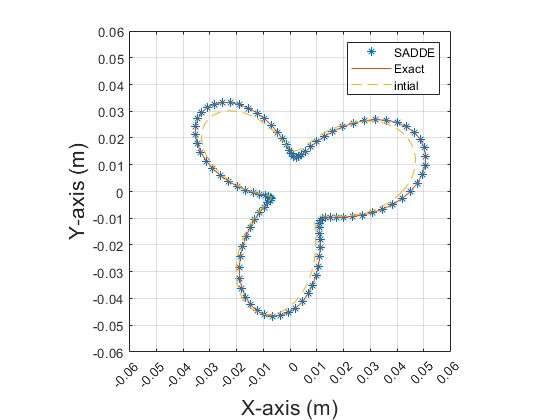


plot(X,Y,'*',x1,y1,x2,y2,'--');
legend('SADDE','Exact','intial');
C=[0 1];
axis square;
% colormap(jet);colorbar;
xlabel('X-axis (m)','fontsize',16);
ylabel('Y-axis (m)','fontsize',16);
box on
grid on
set(gca,'xtick',[-M:0.01:M])
set(gca,'ytick',[-M:0.01:M])
yticklabels([-M:0.01:M]);
% colormapeditor;
axis([-M M -M M]); 



% D = duration(0,0,elapsed_time,'Format','hh:mm:ss');
% title(...
% "Iteration: " + itermax  + ", " + ...
% "time: " + string(D))
